# Separation PDFs 

Here we look at the relative separation PDFs in the model, observations and think of the best ways to compare against theory.

clear all
close all

% Observations
obs_traj = load ('../data/traj_09_03_13_clean.mat');

% delete sections in the Scotia Sea.
obs_traj.Yc(obs_traj.Xc>-82) = NaN;
obs_traj.Xc(obs_traj.Xc>-82) = NaN;

% use forward differencing to estimate the velocity 
Unew = nan*obs_traj.Xc;
Vnew = nan*obs_traj.Xc;
dt = 1*24*3600; 
cor = 110*1e3; 

Unew(1:end-1,:) = diff(obs_traj.Xc)*cor.*cosd(obs_traj.Yc(1:end-1,:))/dt; 
Vnew(1:end-1,:) = diff(obs_traj.Yc)*cor/dt; 

obs_traj.Uc = Unew; 
obs_traj.Vc = Vnew; 

% Models
d=[4, 10];

for i =1:length(d)
    [mod_traj(i).X, mod_traj(i).Y, mod_traj(i).U, mod_traj(i).V, mod_traj(i).T, depth(i)] = loadpairs(d(i));
    
    % get the velocity from forward differencing (will be important for structure functions)
    Unew = nan*mod_traj(i).X;
    Vnew = nan*mod_traj(i).X;
    dt = 1*24*3600; 
    cor = 110*1e3; 
    
    Unew(1:end-1,:) = diff(mod_traj(i).X)*cor.*cosd(mod_traj(i).Y(1:end-1,:))/dt; 
    Vnew(1:end-1,:) = diff(mod_traj(i).Y)*cor/dt; 
    
    mod_traj(i).U = Unew; 
    mod_traj(i).V = Vnew; 
    
    mod_traj(i).U(mod_traj(i).U==-999) = NaN;
    mod_traj(i).V(mod_traj(i).V==-999) = NaN;
    mod_traj(i).Y(mod_traj(i).X>360-70) = NaN;
    mod_traj(i).U(mod_traj(i).X>360-70) = NaN;
    mod_traj(i).V(mod_traj(i).X>360-70) = NaN;
    mod_traj(i).X(mod_traj(i).X>360-70) = NaN;
    
end

depth = -747.2217

depth = -1.4749e+03

% separation time series from observatios
sep_obs = calculate_seperation_timeseries(obs_traj);

%% Settings
plevel = [500 1000 1800]; % how large are the bins
ndays  = 100; % how long to track a pair
pdiff  = 200; % what is the p difference that we allow.

% Distance pairs
distance_class(1).dist = [10,15]*1e3;
distance_class(2).dist = [30,35]*1e3;

%% get the right pairs
for i =1:length(distance_class)
    for j=1:length(plevel)-1
        [obs_pairs(j,i), obs_sep(j,i)] = find_pairs(sep_obs, distance_class(i).dist, [plevel(j) plevel(j+1)], pdiff, ndays);
    end
end

%% calc sep models
for i = 1:length(distance_class)
    for j =1:length(d)
        mod_sep(j,i) = model_sep_calcs(mod_traj(j), distance_class(i).dist); 
    end
end

% obs % convert to separation arrays
% we need this for the pdfs
clear Obs_disp
for i =1:length(distance_class)
    for j =1:length(plevel)-1
            Obs_disp(j,i) = rel_disp(obs_sep(j,i).sep, ndays);
    end
end

% model % convert to separation arrays
for i =1:length(distance_class)
    for j =1:length(d)
            Mod_disp(j,i) = rel_disp(mod_sep(j,i).sep, ndays);
    end
end

momnums = [0.5, 1, 2, 3, 4]; 

% observational moments 
for i =1:length(distance_class)
    for j =1:length(plevel)-1
        clear moments 
        for n = 1:length(momnums) 
            moments(:,n) = moments_separation(Obs_disp(j,i).disp.^0.5, momnums(n));
        end
        Obs_disp(j,i).moments = moments; 
    end
end

% model moments 
for i =1:length(distance_class)
    for j =1:length(depth)
        clear moments 
        for n = 1:length(momnums) 
            moments(:,n) = moments_separation(Mod_disp(j,i).disp.^0.5, momnums(n));
        end
        Mod_disp(j,i).moments = moments; 
    end
end



% convert to CDFs 
edges = linspace(0, 350, 70); % define some bins

% observations 
for i =1:length(distance_class)
    for j =1:length(plevel)-1
        for p =1:100
            Obs_disp(j,i).sep_cdf(:,p) =  histcounts(Obs_disp(j,i).disp(p,:).^0.5/1e3, edges, 'Normalization','cdf'); 
        end
    end
end


%model 
for i =1:length(distance_class)
    for j =1:length(d)
        for p =1:100
            Mod_disp(j,i).sep_cdf(:,p) =  histcounts(Mod_disp(j,i).disp(p,:).^0.5/1e3, edges, 'Normalization','cdf'); 
        end
    end
end

%%
T = (0:99)+0.01;
r = 0.5*(edges(1:end-1) + edges(2:end));

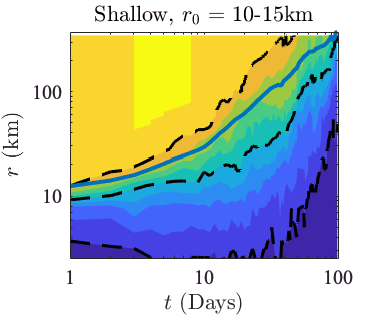

figure('unit','inches','pos',[0. 0. 2.6, 2.2], 'renderer','OpenGL')
levs = [0:0.1:1]; 

% obs 
i=1;  % dist class 
j=1;  % depth 
%subplot(421)
contourf(log10(T), log10(r), Obs_disp(j,i).sep_cdf, levs, 'Edgecolor','none')
caxis([0 1])
hold all
contour(log10(T), log10(r), Obs_disp(j,i).sep_cdf, [0.1, 0.5, 0.9], '--', 'Edgecolor', 'k','linewidth',1)
plot(log10(T), log10(Obs_disp(j,i).avdisp.^0.5/1e3),  'Linewidth',2) 
%ylim([0 ])
xlim([0 2])
%grid on
ticks4x = [log10(1:10) , log10(20:10:100)];
xticks(ticks4x)
xticklabels({'1', '', '','','','','','','','10','','','','','','','','', '100'})
ticks4y = [log10(1:10) , log10(20:10:100), log10(200:100:300)];
yticks(ticks4y)
yticklabels({'1','', '','','','','','','','10','','','','','','','','', '100'})

set(gca,'fontsize', 10, 'fontname','times')
xlabel('$t$ (Days)', 'interpreter', 'latex')
ylabel('$r$ (km)', 'interpreter', 'latex')
title('Shallow, $r_0$ = 10-15km', 'interpreter', 'latex')
print('obsCDF11.eps','-depsc', '-r400')

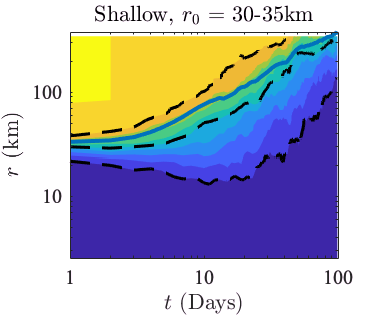

figure('unit','inches','pos',[0. 0. 2.6, 2.2], 'renderer','OpenGL')
levs = [0:0.1:1]; 

% obs 
i=2;  % dist class 
j=1;  % depth 
%subplot(421)
contourf(log10(T), log10(r), Obs_disp(j,i).sep_cdf, levs, 'Edgecolor','none')
caxis([0 1])
hold all
contour(log10(T), log10(r), Obs_disp(j,i).sep_cdf, [0.1, 0.5, 0.9], '--', 'Edgecolor', 'k','linewidth',1)
plot(log10(T), log10(Obs_disp(j,i).avdisp.^0.5/1e3),  'Linewidth',2) 
%ylim([0 ])
xlim([0 2])
%grid on
ticks4x = [log10(1:10) , log10(20:10:100)];
xticks(ticks4x)
xticklabels({'1', '', '','','','','','','','10','','','','','','','','', '100'})
ticks4y = [log10(1:10) , log10(20:10:100), log10(200:100:300)];
yticks(ticks4y)
yticklabels({'1','', '','','','','','','','10','','','','','','','','', '100'})

set(gca,'fontsize', 10, 'fontname','times')
xlabel('$t$ (Days)', 'interpreter', 'latex')
ylabel('$r$ (km)', 'interpreter', 'latex')
title('Shallow, $r_0$ = 30-35km', 'interpreter', 'latex')

print('obsCDF21.eps','-depsc', '-r400')

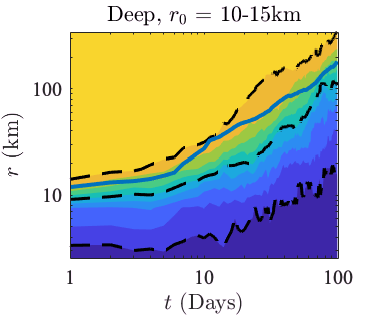

figure('unit','inches','pos',[0. 0. 2.6, 2.2], 'renderer','OpenGL')
levs = [0:0.1:1]; 

% obs 
i=1;  % dist class 
j=2;  % depth 
%subplot(421)
contourf(log10(T), log10(r), Obs_disp(j,i).sep_cdf, levs, 'Edgecolor','none')
caxis([0 1])
hold all
contour(log10(T), log10(r), Obs_disp(j,i).sep_cdf, [0.1, 0.5, 0.9], '--', 'Edgecolor', 'k','linewidth',1)
plot(log10(T), log10(Obs_disp(j,i).avdisp.^0.5/1e3),  'Linewidth',2) 
%ylim([0 ])
xlim([0 2])
%grid on
ticks4x = [log10(1:10) , log10(20:10:100)];
xticks(ticks4x)
xticklabels({'1', '', '','','','','','','','10','','','','','','','','', '100'})
ticks4y = [log10(1:10) , log10(20:10:100), log10(200:100:300)];
yticks(ticks4y)
yticklabels({'1','', '','','','','','','','10','','','','','','','','', '100'})

set(gca,'fontsize', 10, 'fontname','times')
xlabel('$t$ (Days)', 'interpreter', 'latex')
ylabel('$r$ (km)', 'interpreter', 'latex')
title('Deep, $r_0$ = 10-15km', 'interpreter', 'latex')

print('obsCDF12.eps','-depsc', '-r400')

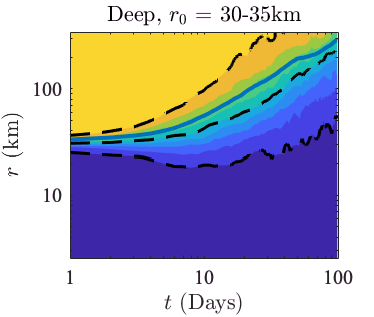

figure('unit','inches','pos',[0. 0. 2.6, 2.2], 'renderer','OpenGL')
levs = [0:0.1:1]; 

% obs 
i=2;  % dist class 
j=2;  % depth 
%subplot(421)
contourf(log10(T), log10(r), Obs_disp(j,i).sep_cdf, levs, 'Edgecolor','none')
caxis([0 1])
hold all
contour(log10(T), log10(r), Obs_disp(j,i).sep_cdf, [0.1, 0.5, 0.9], '--', 'Edgecolor', 'k','linewidth',1)
plot(log10(T), log10(Obs_disp(j,i).avdisp.^0.5/1e3),  'Linewidth',2) 
%ylim([0 ])
xlim([0 2])
%grid on
ticks4x = [log10(1:10) , log10(20:10:100)];
xticks(ticks4x)
xticklabels({'1', '', '','','','','','','','10','','','','','','','','', '100'})
ticks4y = [log10(1:10) , log10(20:10:100), log10(200:100:300)];
yticks(ticks4y)
yticklabels({'1','', '','','','','','','','10','','','','','','','','', '100'})

set(gca,'fontsize', 10, 'fontname','times')
xlabel('$t$ (Days)', 'interpreter', 'latex')
ylabel('$r$ (km)', 'interpreter', 'latex')
title('Deep, $r_0$ = 30-35km', 'interpreter', 'latex')

print('obsCDF22.eps','-depsc', '-r400')

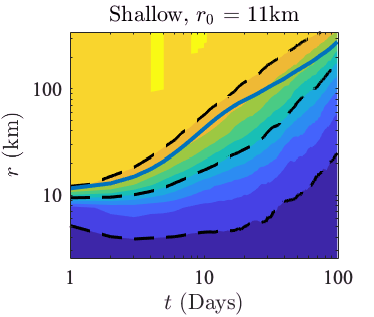

figure('unit','inches','pos',[0. 0. 2.6, 2.2], 'renderer','OpenGL')
levs = [0:0.1:1]; 

% obs 
i=1;  % dist class 
j=1;  % depth 
%subplot(421)
contourf(log10(T), log10(r), Mod_disp(j,i).sep_cdf, levs, 'Edgecolor','none')
caxis([0 1])
hold all
contour(log10(T), log10(r), Mod_disp(j,i).sep_cdf, [0.1, 0.5, 0.9], '--', 'Edgecolor', 'k','linewidth',1)
plot(log10(T), log10(Mod_disp(j,i).avdisp.^0.5/1e3),  'Linewidth',2) 
%ylim([0 ])
xlim([0 2])
%grid on
ticks4x = [log10(1:10) , log10(20:10:100)];
xticks(ticks4x)
xticklabels({'1', '', '','','','','','','','10','','','','','','','','', '100'})
ticks4y = [log10(1:10) , log10(20:10:100), log10(200:100:300)];
yticks(ticks4y)
yticklabels({'1','', '','','','','','','','10','','','','','','','','', '100'})

set(gca,'fontsize', 10, 'fontname','times')
xlabel('$t$ (Days)', 'interpreter', 'latex')
ylabel('$r$ (km)', 'interpreter', 'latex')
title('Shallow, $r_0$ = 11km', 'interpreter', 'latex')

print('modCDF11.eps','-depsc', '-r400')

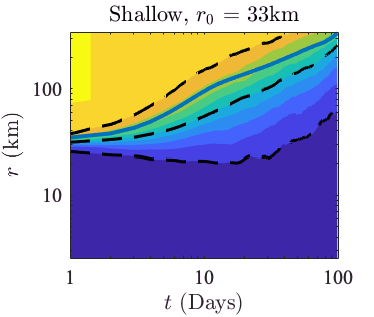

figure('unit','inches','pos',[0. 0. 2.6, 2.2], 'renderer','OpenGL')
levs = [0:0.1:1]; 

% obs 
i=2;  % dist class 
j=1;  % depth 
%subplot(421)
contourf(log10(T), log10(r), Mod_disp(j,i).sep_cdf, levs, 'Edgecolor','none')
caxis([0 1])
hold all
contour(log10(T), log10(r), Mod_disp(j,i).sep_cdf, [0.1, 0.5, 0.9], '--', 'Edgecolor', 'k','linewidth',1)
plot(log10(T), log10(Mod_disp(j,i).avdisp.^0.5/1e3),  'Linewidth',2) 
%ylim([0 ])
xlim([0 2])
%grid on
ticks4x = [log10(1:10) , log10(20:10:100)];
xticks(ticks4x)
xticklabels({'1', '', '','','','','','','','10','','','','','','','','', '100'})
ticks4y = [log10(1:10) , log10(20:10:100), log10(200:100:300)];
yticks(ticks4y)
yticklabels({'1','', '','','','','','','','10','','','','','','','','', '100'})

set(gca,'fontsize', 10, 'fontname','times')
xlabel('$t$ (Days)', 'interpreter', 'latex')
ylabel('$r$ (km)', 'interpreter', 'latex')
title('Shallow, $r_0$ = 33km', 'interpreter', 'latex')

print('modCDF21.eps','-depsc', '-r400')

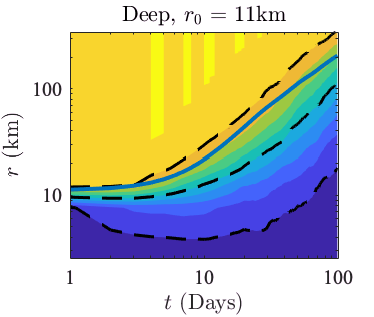

figure('unit','inches','pos',[0. 0. 2.6, 2.2], 'renderer','OpenGL')
levs = [0:0.1:1]; 

% obs 
i=1;  % dist class 
j=2;  % depth 
%subplot(421)
contourf(log10(T), log10(r), Mod_disp(j,i).sep_cdf, levs, 'Edgecolor','none')
caxis([0 1])
hold all
contour(log10(T), log10(r), Mod_disp(j,i).sep_cdf, [0.1, 0.5, 0.9], '--', 'Edgecolor', 'k','linewidth',1)
plot(log10(T), log10(Mod_disp(j,i).avdisp.^0.5/1e3),  'Linewidth',2) 
%ylim([0 ])
xlim([0 2])
%grid on
ticks4x = [log10(1:10) , log10(20:10:100)];
xticks(ticks4x)
xticklabels({'1', '', '','','','','','','','10','','','','','','','','', '100'})
ticks4y = [log10(1:10) , log10(20:10:100), log10(200:100:300)];
yticks(ticks4y)
yticklabels({'1','', '','','','','','','','10','','','','','','','','', '100'})

set(gca,'fontsize', 10, 'fontname','times')
xlabel('$t$ (Days)', 'interpreter', 'latex')
ylabel('$r$ (km)', 'interpreter', 'latex')
title('Deep, $r_0$ = 11km', 'interpreter', 'latex')

print('modCDF12.eps','-depsc', '-r400')

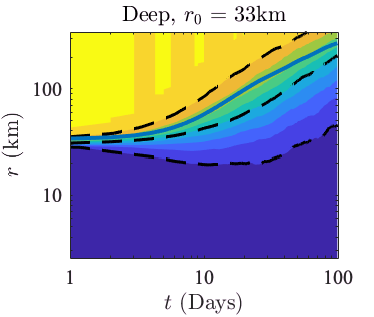

figure('unit','inches','pos',[0. 0. 2.6, 2.2], 'renderer','OpenGL')
levs = [0:0.1:1]; 

% obs 
i=2;  % dist class 
j=2;  % depth 
%subplot(421)
contourf(log10(T), log10(r), Mod_disp(j,i).sep_cdf, levs, 'Edgecolor','none')
caxis([0 1])
hold all
contour(log10(T), log10(r), Mod_disp(j,i).sep_cdf, [0.1, 0.5, 0.9], '--', 'Edgecolor', 'k','linewidth',1)
plot(log10(T), log10(Mod_disp(j,i).avdisp.^0.5/1e3),  'Linewidth',2) 
%ylim([0 ])
xlim([0 2])
%grid on
ticks4x = [log10(1:10) , log10(20:10:100)];
xticks(ticks4x)
xticklabels({'1', '', '','','','','','','','10','','','','','','','','', '100'})
ticks4y = [log10(1:10) , log10(20:10:100), log10(200:100:300)];
yticks(ticks4y)
yticklabels({'1','', '','','','','','','','10','','','','','','','','', '100'})

set(gca,'fontsize', 10, 'fontname','times')
xlabel('$t$ (Days)', 'interpreter', 'latex')
ylabel('$r$ (km)', 'interpreter', 'latex')
title('Deep, $r_0$ = 33km', 'interpreter', 'latex')

print('modCDF22.eps','-depsc', '-r400')

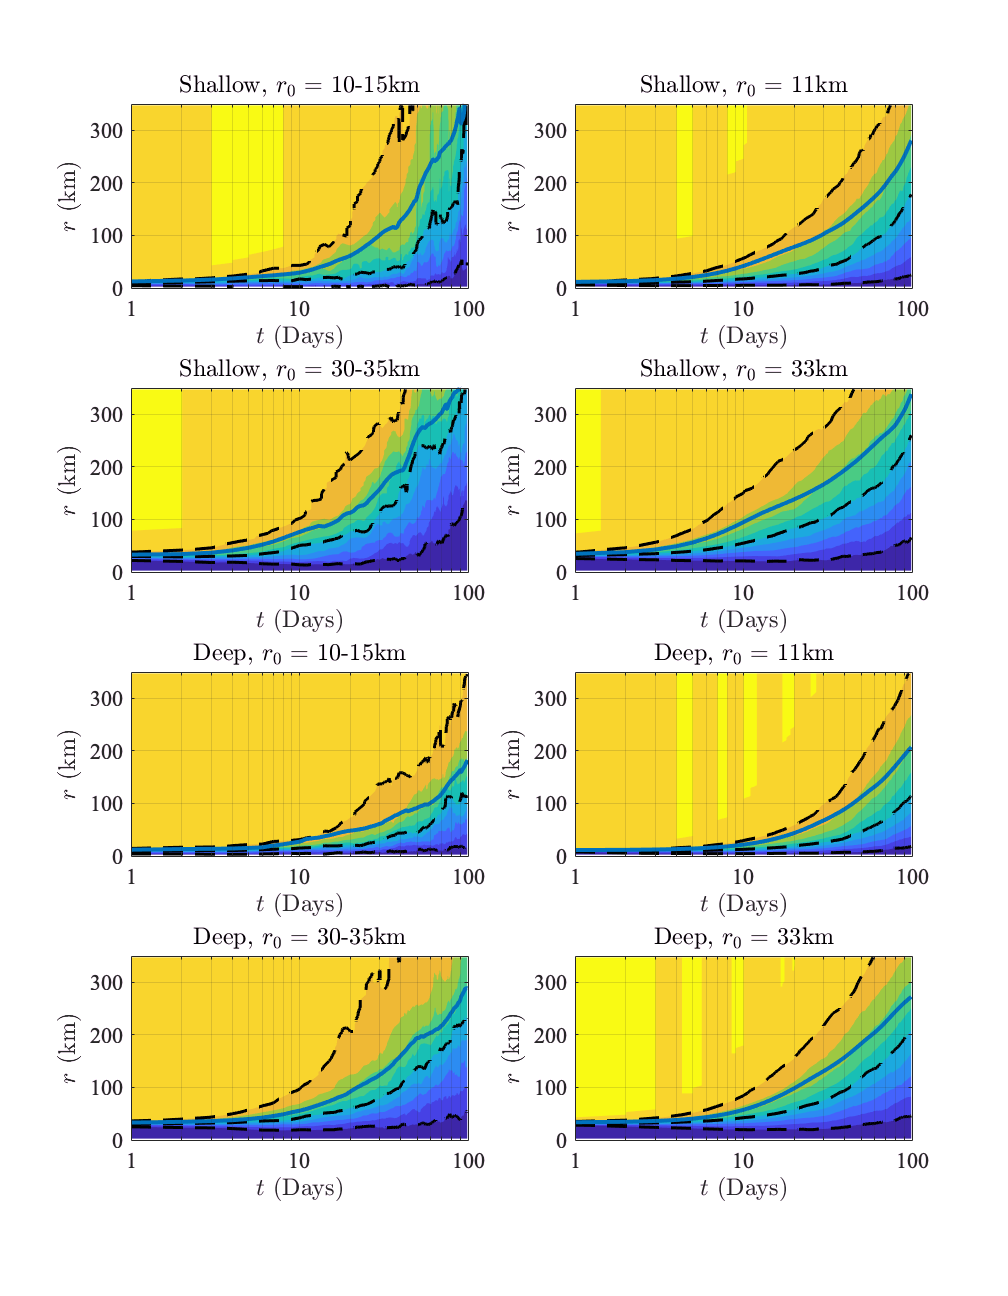

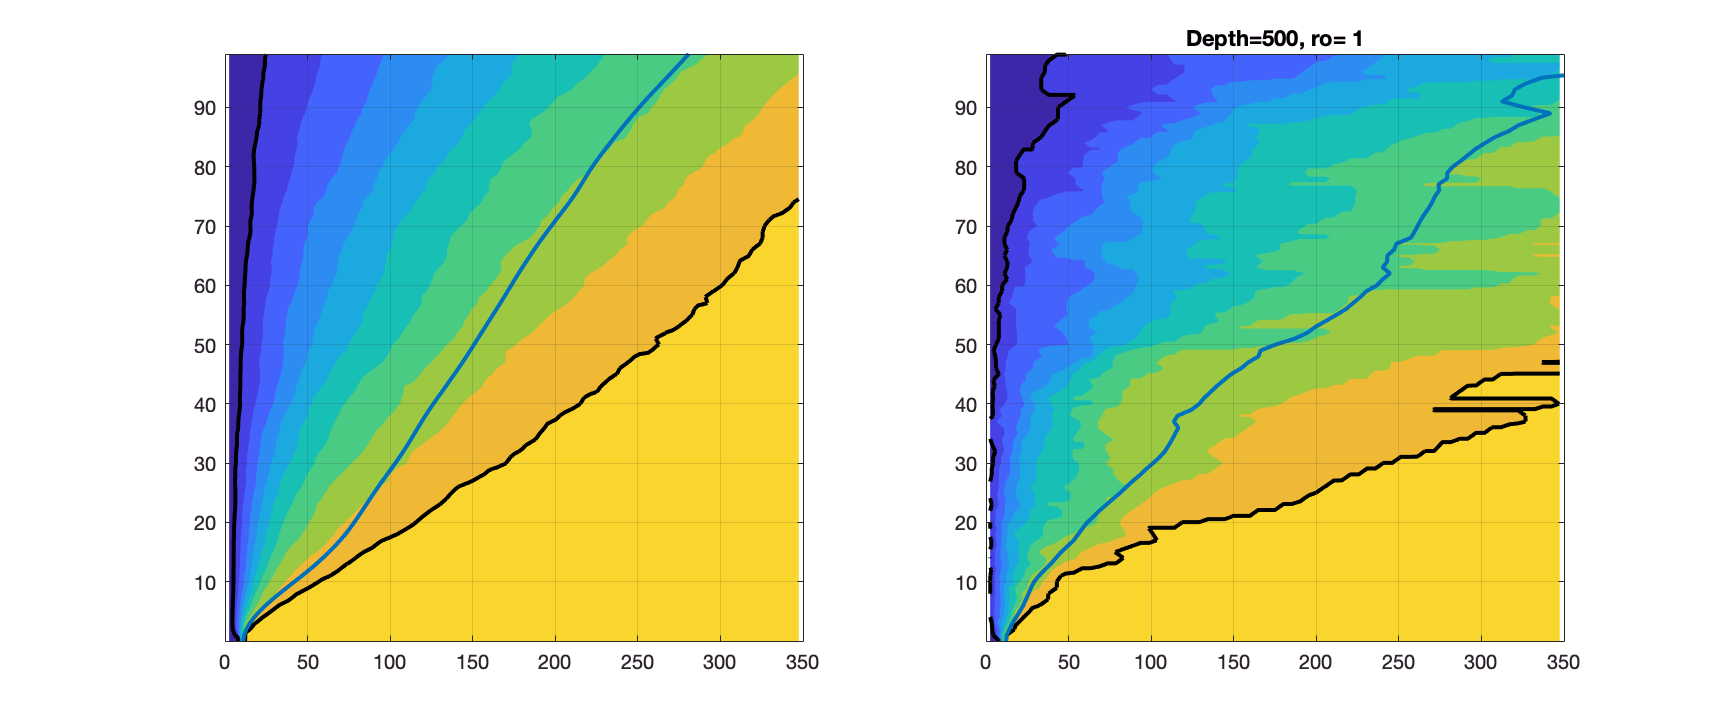

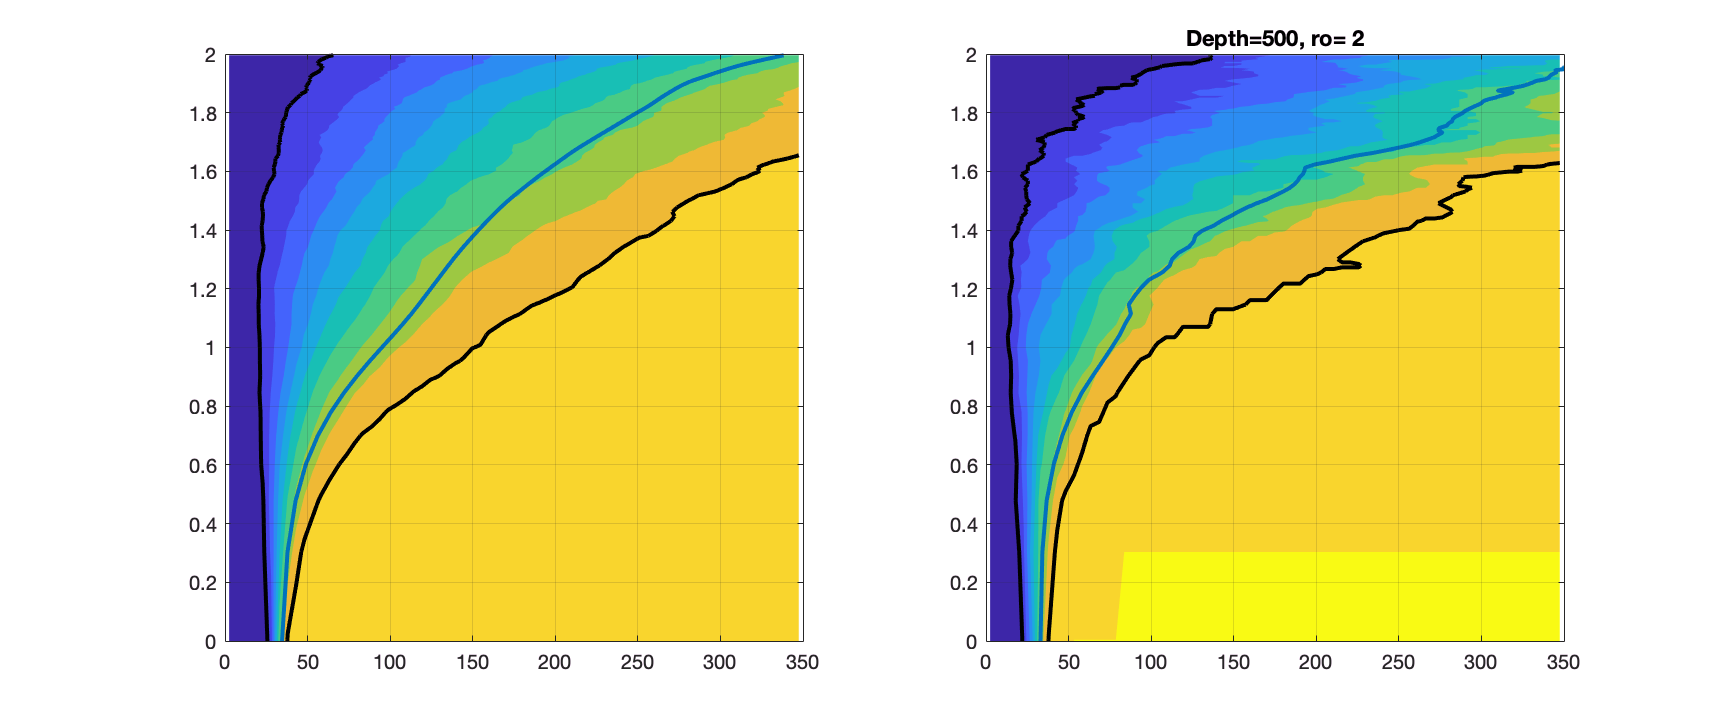

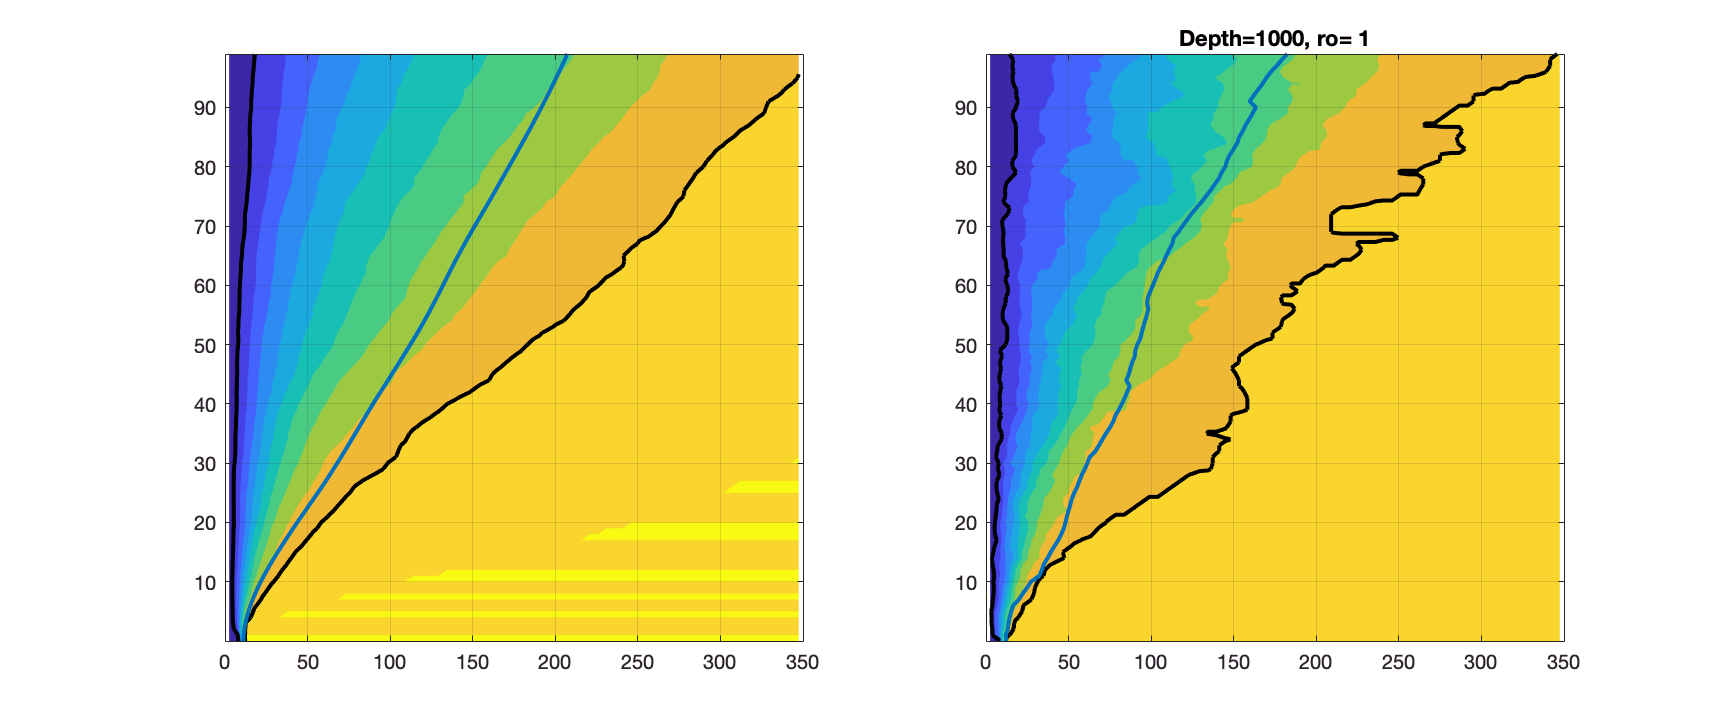

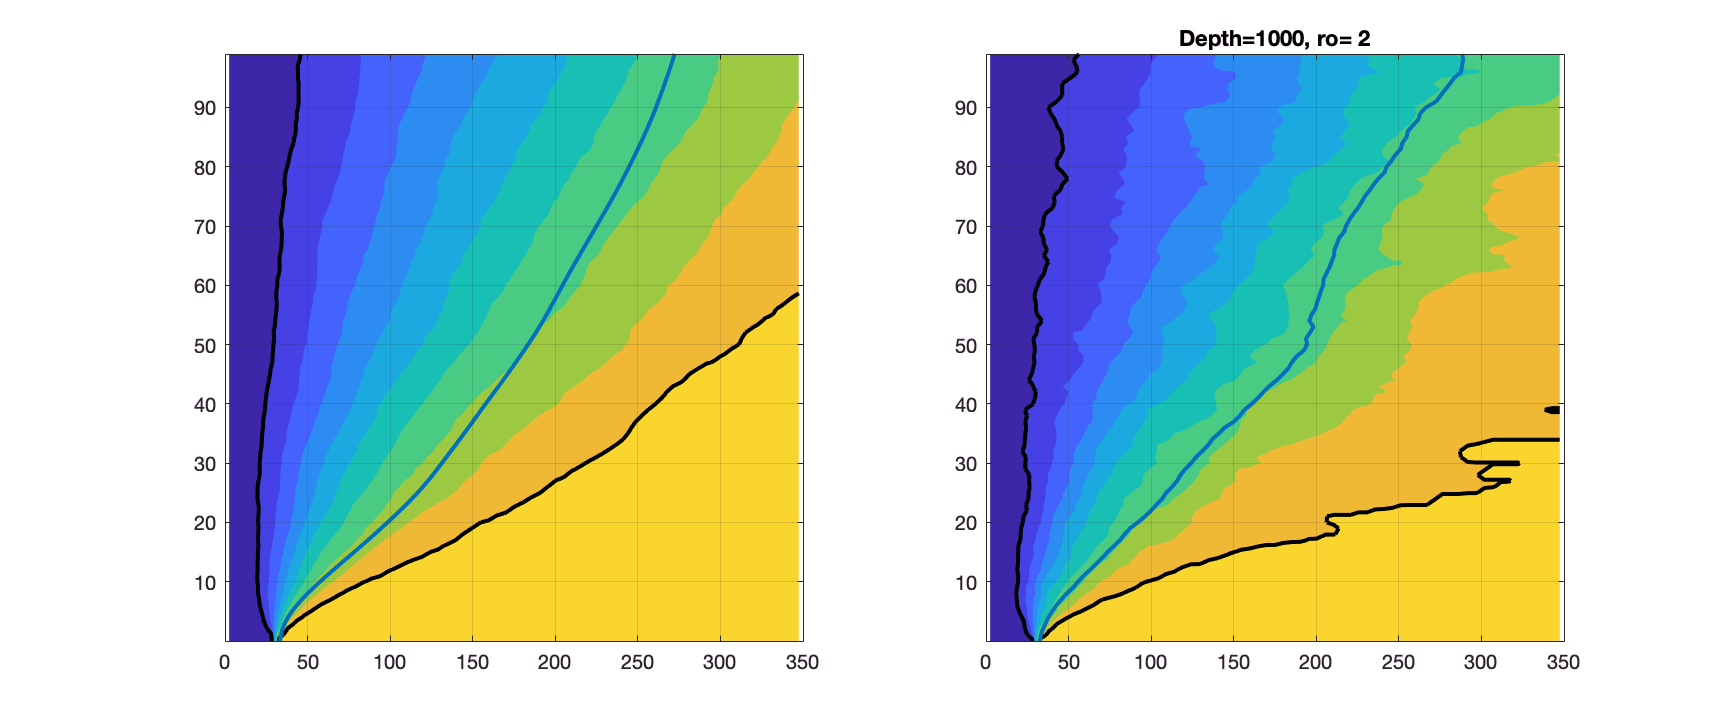

figure('unit','inches','pos',[0. 0. 7, 9])
levs = [0:0.1:1]; 

% obs 
i=1;  % dist class 
j=1;  % depth 
subplot(421)
contourf(log10(T), r, Obs_disp(j,i).sep_cdf, levs, 'Edgecolor','none')
caxis([0 1])
hold all
contour(log10(T), r, Obs_disp(j,i).sep_cdf, [0.1, 0.5, 0.9], '--', 'Edgecolor', 'k','linewidth',1)
plot(log10(T), Obs_disp(j,i).avdisp.^0.5/1e3,  'Linewidth',2) 
ylim([0 350])
xlim([0 2])
grid on
ticks = [log10(1:10) , log10(20:10:100)];
xticks(ticks)
xticklabels({'1', '', '','','','','','','','10','','','','','','','','', '100'})
set(gca,'fontsize', 11, 'fontname','times')
xlabel('$t$ (Days)', 'interpreter', 'latex')
ylabel('$r$ (km)', 'interpreter', 'latex')
title('Shallow, $r_0$ = 10-15km', 'interpreter', 'latex')

i=2; 
j=1; 
subplot(423)
contourf(log10(T), r, Obs_disp(j,i).sep_cdf, levs, 'Edgecolor','none')
caxis([0 1])
hold all
contour(log10(T), r, Obs_disp(j,i).sep_cdf, [0.1, 0.5, 0.9], '--', 'Edgecolor', 'k','linewidth',1)
plot(log10(T), Obs_disp(j,i).avdisp.^0.5/1e3,  'Linewidth',2) 
ylim([0 350])
xlim([0 2])
grid on
ticks = [log10(1:10) , log10(20:10:100)];
xticks(ticks)
xticklabels({'1', '', '','','','','','','','10','','','','','','','','', '100'})
set(gca,'fontsize', 11, 'fontname','times')
xlabel('$t$ (Days)', 'interpreter', 'latex')
ylabel('$r$ (km)', 'interpreter', 'latex')
title('Shallow, $r_0$ = 30-35km', 'interpreter', 'latex')

i=1; 
j=2; 
subplot(4,2,5)
contourf(log10(T), r, Obs_disp(j,i).sep_cdf, levs, 'Edgecolor','none')
caxis([0 1])
hold all
contour(log10(T), r, Obs_disp(j,i).sep_cdf, [0.1, 0.5, 0.9], '--', 'Edgecolor', 'k','linewidth',1)
plot(log10(T), Obs_disp(j,i).avdisp.^0.5/1e3,  'Linewidth',2) 
ylim([0 350])
xlim([0 2])
grid on
ticks = [log10(1:10) , log10(20:10:100)];
xticks(ticks)
xticklabels({'1', '', '','','','','','','','10','','','','','','','','', '100'})
set(gca,'fontsize', 11, 'fontname','times')
xlabel('$t$ (Days)', 'interpreter', 'latex')
ylabel('$r$ (km)', 'interpreter', 'latex')
title('Deep, $r_0$ = 10-15km', 'interpreter', 'latex')

i=2; 
j=2; 
subplot(4,2,7)
contourf(log10(T), r, Obs_disp(j,i).sep_cdf, levs, 'Edgecolor','none')
caxis([0 1])
hold all
contour(log10(T), r, Obs_disp(j,i).sep_cdf, [0.1, 0.5, 0.9], '--', 'Edgecolor', 'k','linewidth',1)
plot(log10(T), Obs_disp(j,i).avdisp.^0.5/1e3,  'Linewidth',2) 
ylim([0 350])
xlim([0 2])
grid on
ticks = [log10(1:10) , log10(20:10:100)];
xticks(ticks)
xticklabels({'1', '', '','','','','','','','10','','','','','','','','', '100'})
set(gca,'fontsize', 11, 'fontname','times')
xlabel('$t$ (Days)', 'interpreter', 'latex')
ylabel('$r$ (km)', 'interpreter', 'latex')
title('Deep, $r_0$ = 30-35km', 'interpreter', 'latex')

i=1; j=1; 
subplot(4,2,2)
contourf(log10(T), r, Mod_disp(j,i).sep_cdf, levs, 'Edgecolor','none')
caxis([0 1])
hold all
contour(log10(T), r, Mod_disp(j,i).sep_cdf, [0.1, 0.5, 0.9], '--', 'Edgecolor', 'k','linewidth',1)
plot(log10(T), Mod_disp(j,i).avdisp.^0.5/1e3,  'Linewidth',2) 
ylim([0 350])
xlim([0 2])
grid on
ticks = [log10(1:10) , log10(20:10:100)];
xticks(ticks)
xticklabels({'1', '', '','','','','','','','10','','','','','','','','', '100'})
set(gca,'fontsize', 11, 'fontname','times')
xlabel('$t$ (Days)', 'interpreter', 'latex')
ylabel('$r$ (km)', 'interpreter', 'latex')
title('Shallow, $r_0$ = 11km', 'interpreter', 'latex')

i=2; j=1; 
subplot(4,2,4)
contourf(log10(T), r, Mod_disp(j,i).sep_cdf, levs, 'Edgecolor','none')
caxis([0 1])
hold all
contour(log10(T), r, Mod_disp(j,i).sep_cdf, [0.1, 0.5, 0.9], '--', 'Edgecolor', 'k','linewidth',1)
plot(log10(T), Mod_disp(j,i).avdisp.^0.5/1e3,  'Linewidth',2) 
ylim([0 350])
xlim([0 2])
grid on
ticks = [log10(1:10) , log10(20:10:100)];
xticks(ticks)
xticklabels({'1', '', '','','','','','','','10','','','','','','','','', '100'})
set(gca,'fontsize', 11, 'fontname','times')
xlabel('$t$ (Days)', 'interpreter', 'latex')
ylabel('$r$ (km)', 'interpreter', 'latex')
title('Shallow, $r_0$ = 33km', 'interpreter', 'latex')

i=1; j=2; 
subplot(4,2,6)
contourf(log10(T), r, Mod_disp(j,i).sep_cdf, levs, 'Edgecolor','none')
caxis([0 1])
hold all
contour(log10(T), r, Mod_disp(j,i).sep_cdf, [0.1, 0.5, 0.9], '--', 'Edgecolor', 'k','linewidth',1)
plot(log10(T), Mod_disp(j,i).avdisp.^0.5/1e3,  'Linewidth',2) 
ylim([0 350])
xlim([0 2])
grid on
ticks = [log10(1:10) , log10(20:10:100)];
xticks(ticks)
xticklabels({'1', '', '','','','','','','','10','','','','','','','','', '100'})
set(gca,'fontsize', 11, 'fontname','times')
xlabel('$t$ (Days)', 'interpreter', 'latex')
ylabel('$r$ (km)', 'interpreter', 'latex')
title('Deep, $r_0$ = 11km', 'interpreter', 'latex')

i=2; j=2; 
subplot(4,2,8)
contourf(log10(T), r, Mod_disp(j,i).sep_cdf, levs, 'Edgecolor','none')
caxis([0 1])
hold all
contour(log10(T), r, Mod_disp(j,i).sep_cdf, [0.1, 0.5, 0.9], '--', 'Edgecolor', 'k','linewidth',1)
plot(log10(T), Mod_disp(j,i).avdisp.^0.5/1e3,  'Linewidth',2) 
ylim([0 350])
xlim([0 2])
grid on
ticks = [log10(1:10) , log10(20:10:100)];
xticks(ticks)
xticklabels({'1', '', '','','','','','','','10','','','','','','','','', '100'})
set(gca,'fontsize', 11, 'fontname','times')
xlabel('$t$ (Days)', 'interpreter', 'latex')
ylabel('$r$ (km)', 'interpreter', 'latex')
title('Deep, $r_0$ = 33km', 'interpreter', 'latex')

print('CDFs.eps', '-depsc')

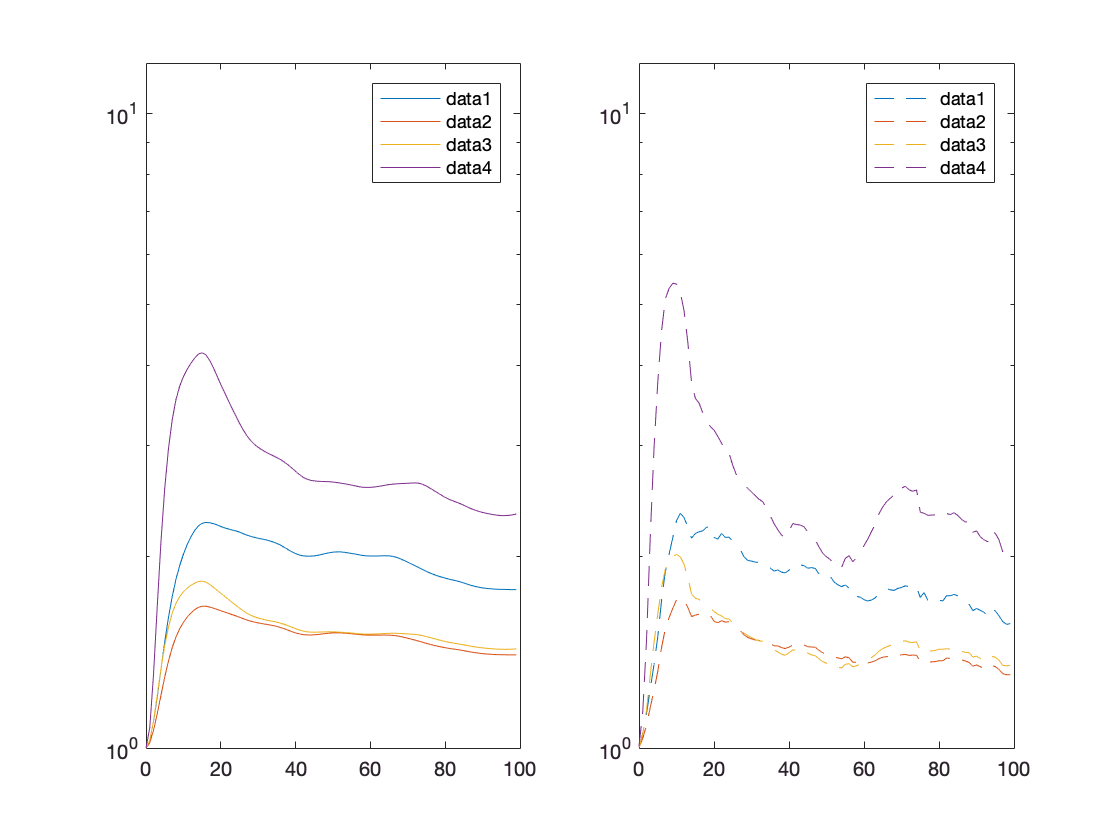

% moment ratio plots 
% example Ku = <r^4>/<r^2>^2
% but lower versions of this are less impacted by the tails 
% <r^2>/<r^0.5>^4, <r^2>/<r>^2, <r^3>/<r^2>^3/2 *skewness, <r^4>/<r^2>^2 *kurtosis

figure 
i=2;
j=1; 

subplot(121)
semilogy(T, Mod_disp(j,i).moments(:,3)./Mod_disp(j,i).moments(:,1).^4)
hold all 
semilogy(T, Mod_disp(j,i).moments(:,3)./Mod_disp(j,i).moments(:,2).^2)
semilogy(T, Mod_disp(j,i).moments(:,4)./Mod_disp(j,i).moments(:,3).^(3/2))
semilogy(T, Mod_disp(j,i).moments(:,5)./Mod_disp(j,i).moments(:,3).^2)

legend('show')
ylim([1, 12])


subplot(122)
semilogy(T, Obs_disp(j,i).moments(:,3)./Obs_disp(j,i).moments(:,1).^4, '--')
hold all 
semilogy(T, Obs_disp(j,i).moments(:,3)./Obs_disp(j,i).moments(:,2).^2, '--')
semilogy(T, Obs_disp(j,i).moments(:,4)./Obs_disp(j,i).moments(:,3).^(3/2), '--')
semilogy(T, Obs_disp(j,i).moments(:,5)./Obs_disp(j,i).moments(:,3).^2, '--')
legend('show')
ylim([1, 12])

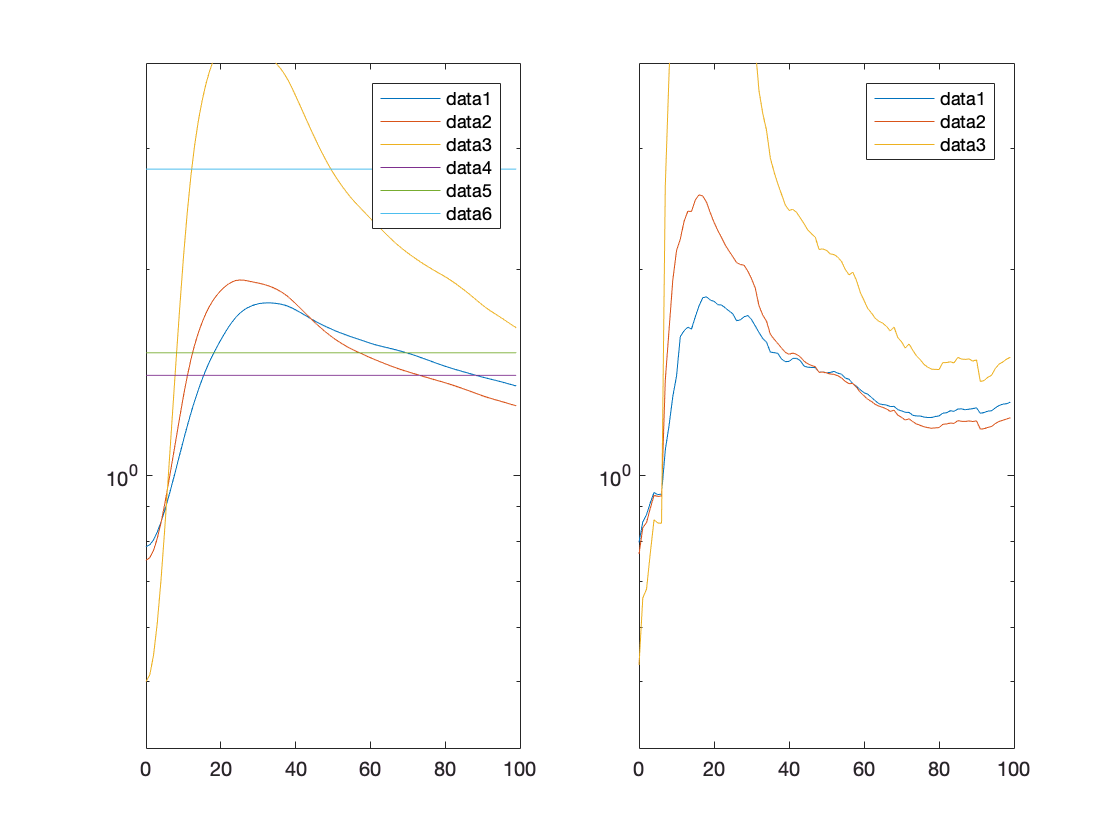

% moment ratio plots 
% example Ku = <r^4>/<r^2>^2
% but lower versions of this are less impacted by the tails 
% <r^2>/<r^0.5>^4, <r^2>/<r>^2, <r^3>/<r^2>^3/2 *skewness, <r^4>/<r^2>^2 *kurtosis

figure 
i=1;
j=2; 

subplot(121)
semilogy(T, Mod_disp(j,i).moments(:,3)./Mod_disp(j,i).moments(:,2).^2/1.27)
hold all
semilogy(T, Mod_disp(j,i).moments(:,4)./Mod_disp(j,i).moments(:,3).^(3/2)/1.33)
semilogy(T, Mod_disp(j,i).moments(:,5)./Mod_disp(j,i).moments(:,3).^2/2.0)

semilogy(T, T./T*1.4)
semilogy(T, T./T*1.51)
semilogy(T, T./T*2.8)

legend('show')
ylim([0.4, 4])


subplot(122)
semilogy(T, Obs_disp(j,i).moments(:,3)./Obs_disp(j,i).moments(:,2).^2/1.27)
hold all 
semilogy(T, Obs_disp(j,i).moments(:,4)./Obs_disp(j,i).moments(:,3).^(3/2)/1.33)
semilogy(T, Obs_disp(j,i).moments(:,5)./Obs_disp(j,i).moments(:,3).^2/2.)
legend('show')
ylim([0.4, 4])

# Hypothesis testing: 

Are the PDFs derived from any of the theoretical PDFs. 

Tdisp = [0:99]'; 
%load fit_params.mat

% observations 
clear fitting_mod fitting_obs

for i =1:length(distance_class)
    for j =1:length(plevel)-1
        fitting_obs(j,i) = dispersion_fitting_overtime(Obs_disp(j,i).avdisp, Tdisp, 3, 50); 
    end
end


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the default value of the function tolerance.

<stopping criteria details>


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the default value of the 


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the default value of the function tolerance.

<stopping criteria details>


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the default value of the 


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the default value of the function tolerance.

<stopping criteria details>


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the default value of the 


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the default value of the function tolerance.

<stopping criteria details>


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the default value of the 


% Model 
for i =1:length(distance_class)
    for j =1:length(depth)
        fitting_mod(j,i) = dispersion_fitting_overtime(Mod_disp(j,i).avdisp, Tdisp, 3, 50); 
    end
end


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the default value of the function tolerance.

<stopping criteria details>


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the default value of the 


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the default value of the function tolerance.

<stopping criteria details>


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the default value of the 


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the default value of the function tolerance.

<stopping criteria details>


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the default value of the 


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the default value of the function tolerance.

<stopping criteria details>


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the default value of the 

save fit_params.mat fitting_obs fitting_mod

colors = lines(4); 
Tfit_ax = 3:50; 

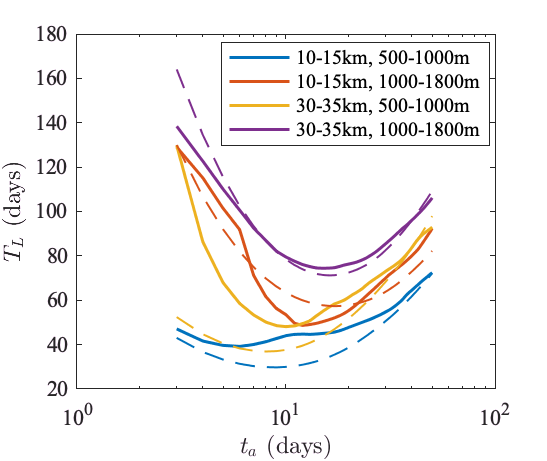

figure('unit','inches','pos',[0. 0. 3.8, 3.2], 'renderer','painters')
n=1;
for i =1:length(distance_class)
    for j =1:length(depth)    
        semilogx(Tfit_ax, fitting_obs(j,i).Tlung, 'color', colors(n,:),'linewidth', 1.5) 
        hold all
        n=n+1; 
    end
end
%legend('show')
n=1; 
for i =1:length(distance_class)
    for j =1:length(depth)    
        semilogx(Tfit_ax,fitting_mod(j,i).Tlung, '--', 'color', colors(n,:),'linewidth', 1) 
        n=n+1; 
    end
end
legend({'10-15km, 500-1000m', '10-15km, 1000-1800m', '30-35km, 500-1000m', '30-35km, 1000-1800m'},'location','best');
xlabel('$t_a$ (days)', 'Interpreter','Latex')
ylabel('$T_L$ (days)', 'Interpreter','Latex')

set(gca,'fontsize',11, 'fontname','Times')
print('Tl_fit.eps', '-depsc')

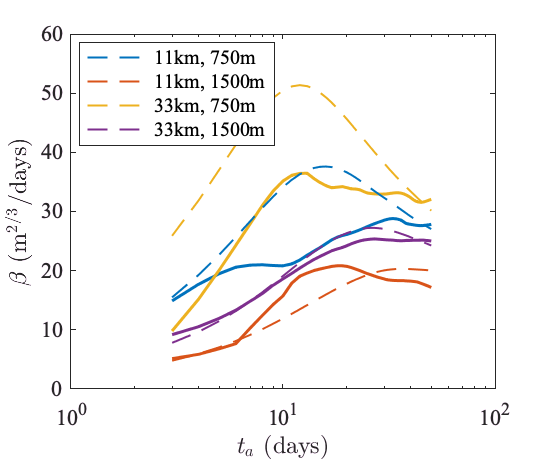

figure('unit','inches','pos',[0. 0. 3.8, 3.2], 'renderer','painters')
n=1;
for i =1:length(distance_class)
    for j =1:length(depth)    
        semilogx(Tfit_ax, fitting_obs(j,i).beta, 'color', colors(n,:),'linewidth', 1.5) 
        hold all
        n=n+1; 
    end
end
n=1; 
for i =1:length(distance_class)
    for j =1:length(depth)    
        g(n) = semilogx(Tfit_ax,fitting_mod(j,i).beta, '--', 'color', colors(n,:),'linewidth', 1.) ;
        n=n+1; 
    end
end
legend(g, {'11km, 750m', '11km, 1500m', '33km, 750m', '33km, 1500m'},'location','best')
xlabel('$t_a$ (days)', 'Interpreter','Latex')
ylabel('$\beta$ (m$^{2/3}$/days)', 'Interpreter','Latex')

set(gca,'fontsize',11, 'fontname','Times')
print('beta_fit.eps', '-depsc')

Check p values to see how well things are fit to theoretical curves. 

% generate samples 

xsamp = 0:1000; % r axis
r0 = 10; % initial separation
Tlung =30; % lungdren time scale 
Tsamp = 10; % when was the PDF samples 
Theory_pdf = 2*pi*xsamp.*lungdrendistfull(xsamp, r0, Tsamp, Tlung, 0); 

Sampspdf1 = pdfrnd(xsamp, Theory_pdf, 1000000); % theoretical pdf 

Sampspdf2 = pdfrnd(xsamp, Theory_pdf, 50); 
[h,p] = kstest2(Sampspdf1, Sampspdf2); 

for i =1:length(distance_class)
    
    for j =1:length(depth)    
        disp(i), disp(j)
        seps = Mod_disp(j,i).disp.^0.5;
        
        r0 = Mod_disp(j,i).avdisp(1).^0.5;  %[m]
        
        clear p_lung h_lung p_rich h_rich
        
        ndays = 100;
        
        for idTa =1:length(fitting_mod(j,i).Tlung)
            
            Tlung  = fitting_mod(j,i).Tlung(idTa)*24*3600; %[s]
            beta = fitting_mod(j,i).beta(idTa)/24/3600;  %[m^2/3/s]
            
            for idT =3:ndays
                
                maxL = max(seps(idT,:))/1e3;
                
                xsamp = 1+(0:maxL+2000)*1000;
                
                Lung_pdf = 2*pi*xsamp.*lungdrendistfull(xsamp, r0, Tdisp(idT)*24*3600, Tlung, 0);
                Rich_pdf = 2*pi*xsamp.*richdistfull(xsamp, r0, Tdisp(idT)*24*3600, beta, 0);
                
                Lung_samp = pdfrnd(xsamp, Lung_pdf, 10000);
                Rich_samp = pdfrnd(xsamp, Rich_pdf, 10000);
                
                True_samp = seps(idT,:);
                
                [h_lung(idT,idTa), fitting_mod(j,i).p_lung(idT,idTa)] = kstest2(True_samp, Lung_samp);
                [h_rich(idT,idTa), fitting_mod(j,i).p_rich(idT,idTa)] = kstest2(True_samp, Rich_samp);
                
            end
        end
    end
end

     1

     1



     1

     2



     2

     1



     2

     2



for i =1:length(distance_class)
    for j =1:length(plevel)-1   
        disp(i), disp(j)
        seps = Obs_disp(j,i).disp.^0.5;
        
        r0 = Obs_disp(j,i).avdisp(1).^0.5;  %[m]
        
        clear p_lung h_lung p_rich h_rich
        
        ndays = 100;
        for idTa =1:length(fitting_obs(j,i).Tlung)
            
            Tlung  = fitting_obs(j,i).Tlung(idTa)*24*3600; %[s]
            beta = fitting_obs(j,i).beta(idTa)/24/3600;  %[m^2/3/s]
            
            for idT =3:ndays
                
                maxL = max(seps(idT,:))/1e3;
                
                xsamp = 1+(0:maxL+2000)*1000;
                
                Lung_pdf = 2*pi*xsamp.*lungdrendistfull(xsamp, r0, Tdisp(idT)*24*3600, Tlung, 0);
                Rich_pdf = 2*pi*xsamp.*richdistfull(xsamp, r0, Tdisp(idT)*24*3600, beta, 0);
                
                Lung_samp = pdfrnd(xsamp, Lung_pdf, 10000);
                Rich_samp = pdfrnd(xsamp, Rich_pdf, 10000);
                
                True_samp = seps(idT,:);
                
                [h_lung(idT,idTa), fitting_obs(j,i).p_lung(idT,idTa)] = kstest2(True_samp, Lung_samp);
                [h_rich(idT,idTa), fitting_obs(j,i).p_rich(idT,idTa)] = kstest2(True_samp, Rich_samp);
                
            end
        end
    end
end

     1

     1



     1

     2



     2

     1



     2

     2



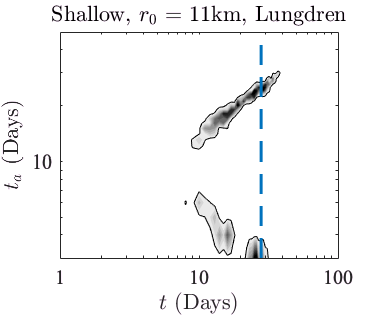

figure('unit','inches','pos',[0. 0. 2.6, 2.2], 'renderer','OpenGL')
levs = [0:0.05:1]; 

colormap(flipud(gray))
% obs 
i=1;  % dist class 
j=1;  % depth 

id = find( Mod_disp(j,i).avdisp.^0.5/1e3<=100 ,1, 'last');

contourf(log10(Tdisp+0.01), log10(Tfit_ax), fitting_mod(j,i).p_lung', levs, 'edgecolor', 'none')
caxis([0 0.6])
hold all 
contour(log10(Tdisp+0.01), log10(Tfit_ax), fitting_mod(j,i).p_lung', [0.05 0.05], 'edgecolor', 'k')
plot( log10(Tdisp(id)+0.01)* Tfit_ax./Tfit_ax, log10(Tfit_ax), '--', 'linewidth',1.5)

xlabel('t (days)')
xlim([0 2])

ticks4x = [log10(1:10) , log10(20:10:100)];
xticks(ticks4x)
xticklabels({'1', '', '','','','','','','','10','','','','','','','','', '100'})
ticks4y = [log10(1:10) , log10(20:10:100), log10(200:100:300)];
yticks(ticks4y)
yticklabels({'1','', '','','','','','','','10','','','','','','','','', '100'})

set(gca,'fontsize', 10, 'fontname','times')
xlabel('$t$ (Days)', 'interpreter', 'latex')
ylabel('$t_a$ (Days)', 'interpreter', 'latex')
title('Shallow, $r_0$ = 11km, Lungdren', 'interpreter', 'latex')

print('modKS_lung_11.eps','-depsc', '-r400')

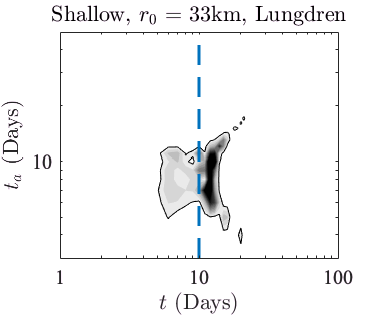

figure('unit','inches','pos',[0. 0. 2.6, 2.2], 'renderer','OpenGL')
levs = [0:0.05:1]; 

colormap(flipud(gray))
% obs 
i=2;  % dist class 
j=1;  % depth 

id = find( Mod_disp(j,i).avdisp.^0.5/1e3<=100 ,1, 'last');

contourf(log10(Tdisp+0.01), log10(Tfit_ax), fitting_mod(j,i).p_lung', levs, 'edgecolor', 'none')
caxis([0 0.6])
hold all 
contour(log10(Tdisp+0.01), log10(Tfit_ax), fitting_mod(j,i).p_lung', [0.05 0.05], 'edgecolor', 'k')
plot( log10(Tdisp(id)+0.01)* Tfit_ax./Tfit_ax, log10(Tfit_ax), '--', 'linewidth',1.5)

xlabel('t (days)')
xlim([0 2])

ticks4x = [log10(1:10) , log10(20:10:100)];
xticks(ticks4x)
xticklabels({'1', '', '','','','','','','','10','','','','','','','','', '100'})
ticks4y = [log10(1:10) , log10(20:10:100), log10(200:100:300)];
yticks(ticks4y)
yticklabels({'1','', '','','','','','','','10','','','','','','','','', '100'})

set(gca,'fontsize', 10, 'fontname','times')
xlabel('$t$ (Days)', 'interpreter', 'latex')
ylabel('$t_a$ (Days)', 'interpreter', 'latex')
title('Shallow, $r_0$ = 33km, Lungdren', 'interpreter', 'latex')

print('modKS_lung_21.eps','-depsc', '-r400')

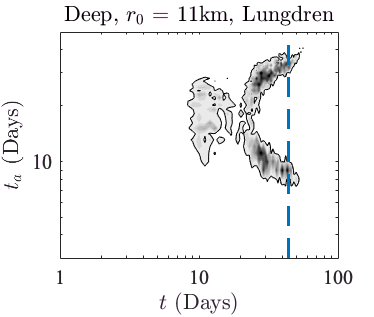

figure('unit','inches','pos',[0. 0. 2.6, 2.2], 'renderer','OpenGL')
levs = [0:0.05:1]; 

colormap(flipud(gray))
% obs 
i=1;  % dist class 
j=2;  % depth 

id = find( Mod_disp(j,i).avdisp.^0.5/1e3<=100 ,1, 'last');

contourf(log10(Tdisp+0.01), log10(Tfit_ax), fitting_mod(j,i).p_lung', levs, 'edgecolor', 'none')
caxis([0 0.6])
hold all 
contour(log10(Tdisp+0.01), log10(Tfit_ax), fitting_mod(j,i).p_lung', [0.05 0.05], 'edgecolor', 'k')
plot( log10(Tdisp(id)+0.01)* Tfit_ax./Tfit_ax, log10(Tfit_ax), '--', 'linewidth',1.5)

xlabel('t (days)')
xlim([0 2])

ticks4x = [log10(1:10) , log10(20:10:100)];
xticks(ticks4x)
xticklabels({'1', '', '','','','','','','','10','','','','','','','','', '100'})
ticks4y = [log10(1:10) , log10(20:10:100), log10(200:100:300)];
yticks(ticks4y)
yticklabels({'1','', '','','','','','','','10','','','','','','','','', '100'})

set(gca,'fontsize', 10, 'fontname','times')
xlabel('$t$ (Days)', 'interpreter', 'latex')
ylabel('$t_a$ (Days)', 'interpreter', 'latex')
title('Deep, $r_0$ = 11km, Lungdren', 'interpreter', 'latex')

print('modKS_lung_12.eps','-depsc', '-r400')

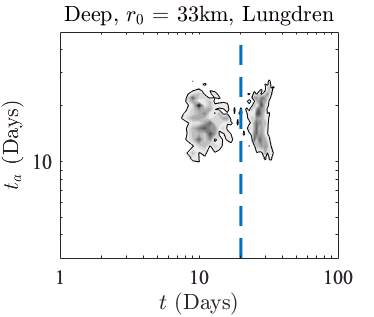

figure('unit','inches','pos',[0. 0. 2.6, 2.2], 'renderer','OpenGL')
levs = [0:0.05:1]; 

colormap(flipud(gray))
% obs 
i=2;  % dist class 
j=2;  % depth 

id = find( Mod_disp(j,i).avdisp.^0.5/1e3<=100 ,1, 'last');

contourf(log10(Tdisp+0.01), log10(Tfit_ax), fitting_mod(j,i).p_lung', levs, 'edgecolor', 'none')
caxis([0 0.6])
hold all 
contour(log10(Tdisp+0.01), log10(Tfit_ax), fitting_mod(j,i).p_lung', [0.05 0.05], 'edgecolor', 'k')
plot( log10(Tdisp(id)+0.01)* Tfit_ax./Tfit_ax, log10(Tfit_ax), '--', 'linewidth',1.5)

xlabel('t (days)')
xlim([0 2])

ticks4x = [log10(1:10) , log10(20:10:100)];
xticks(ticks4x)
xticklabels({'1', '', '','','','','','','','10','','','','','','','','', '100'})
ticks4y = [log10(1:10) , log10(20:10:100), log10(200:100:300)];
yticks(ticks4y)
yticklabels({'1','', '','','','','','','','10','','','','','','','','', '100'})

set(gca,'fontsize', 10, 'fontname','times')
xlabel('$t$ (Days)', 'interpreter', 'latex')
ylabel('$t_a$ (Days)', 'interpreter', 'latex')
title('Deep, $r_0$ = 33km, Lungdren', 'interpreter', 'latex')

print('modKS_lung_22.eps','-depsc', '-r400')

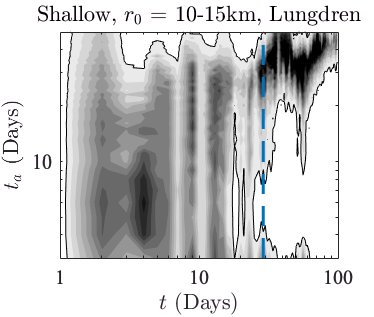

figure('unit','inches','pos',[0. 0. 2.6, 2.2], 'renderer','OpenGL')
levs = [0:0.05:1]; 

colormap(flipud(gray))
% obs 
i=1;  % dist class 
j=1;  % depth 

id = find( Obs_disp(j,i).avdisp.^0.5/1e3<=100 ,1, 'last');

contourf(log10(Tdisp+0.01), log10(Tfit_ax), fitting_obs(j,i).p_lung', levs, 'edgecolor', 'none')
caxis([0 0.6])
hold all 
contour(log10(Tdisp+0.01), log10(Tfit_ax), fitting_obs(j,i).p_lung', [0.05 0.05], 'edgecolor', 'k')
plot( log10(Tdisp(id)+0.01)* Tfit_ax./Tfit_ax, log10(Tfit_ax), '--', 'linewidth',1.5)

xlabel('t (days)')
xlim([0 2])

ticks4x = [log10(1:10) , log10(20:10:100)];
xticks(ticks4x)
xticklabels({'1', '', '','','','','','','','10','','','','','','','','', '100'})
ticks4y = [log10(1:10) , log10(20:10:100), log10(200:100:300)];
yticks(ticks4y)
yticklabels({'1','', '','','','','','','','10','','','','','','','','', '100'})

set(gca,'fontsize', 10, 'fontname','times')
xlabel('$t$ (Days)', 'interpreter', 'latex')
ylabel('$t_a$ (Days)', 'interpreter', 'latex')
title('Shallow, $r_0$ = 10-15km, Lungdren', 'interpreter', 'latex')

print('obsKS_lung_11.eps','-depsc', '-r400')

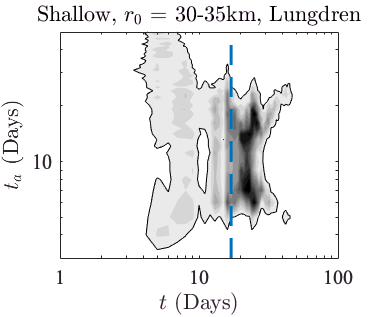

figure('unit','inches','pos',[0. 0. 2.6, 2.2], 'renderer','OpenGL')
levs = [0:0.05:1]; 

colormap(flipud(gray))
% obs 
i=2;  % dist class 
j=1;  % depth 

id = find( Obs_disp(j,i).avdisp.^0.5/1e3<=100 ,1, 'last');

contourf(log10(Tdisp+0.01), log10(Tfit_ax), fitting_obs(j,i).p_lung', levs, 'edgecolor', 'none')
caxis([0 0.6])
hold all 
contour(log10(Tdisp+0.01), log10(Tfit_ax), fitting_obs(j,i).p_lung', [0.05 0.05], 'edgecolor', 'k')
plot( log10(Tdisp(id)+0.01)* Tfit_ax./Tfit_ax, log10(Tfit_ax), '--', 'linewidth',1.5)

xlabel('t (days)')
xlim([0 2])

ticks4x = [log10(1:10) , log10(20:10:100)];
xticks(ticks4x)
xticklabels({'1', '', '','','','','','','','10','','','','','','','','', '100'})
ticks4y = [log10(1:10) , log10(20:10:100), log10(200:100:300)];
yticks(ticks4y)
yticklabels({'1','', '','','','','','','','10','','','','','','','','', '100'})

set(gca,'fontsize', 10, 'fontname','times')
xlabel('$t$ (Days)', 'interpreter', 'latex')
ylabel('$t_a$ (Days)', 'interpreter', 'latex')
title('Shallow, $r_0$ = 30-35km, Lungdren', 'interpreter', 'latex')

print('obsKS_lung_21.eps','-depsc', '-r400')

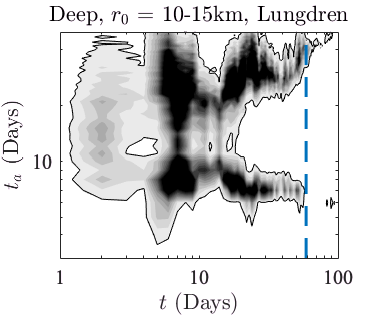

figure('unit','inches','pos',[0. 0. 2.6, 2.2], 'renderer','OpenGL')
levs = [0:0.05:1]; 

colormap(flipud(gray))
% obs 
i=1;  % dist class 
j=2;  % depth 

id = find( Obs_disp(j,i).avdisp.^0.5/1e3<=100 ,1, 'last');

contourf(log10(Tdisp+0.01), log10(Tfit_ax), fitting_obs(j,i).p_lung', levs, 'edgecolor', 'none')
caxis([0 0.6])
hold all 
contour(log10(Tdisp+0.01), log10(Tfit_ax), fitting_obs(j,i).p_lung', [0.05 0.05], 'edgecolor', 'k')
plot( log10(Tdisp(id)+0.01)* Tfit_ax./Tfit_ax, log10(Tfit_ax), '--', 'linewidth',1.5)

xlabel('t (days)')
xlim([0 2])

ticks4x = [log10(1:10) , log10(20:10:100)];
xticks(ticks4x)
xticklabels({'1', '', '','','','','','','','10','','','','','','','','', '100'})
ticks4y = [log10(1:10) , log10(20:10:100), log10(200:100:300)];
yticks(ticks4y)
yticklabels({'1','', '','','','','','','','10','','','','','','','','', '100'})

set(gca,'fontsize', 10, 'fontname','times')
xlabel('$t$ (Days)', 'interpreter', 'latex')
ylabel('$t_a$ (Days)', 'interpreter', 'latex')
title('Deep, $r_0$ = 10-15km, Lungdren', 'interpreter', 'latex')

print('obsKS_lung_12.eps','-depsc', '-r400')

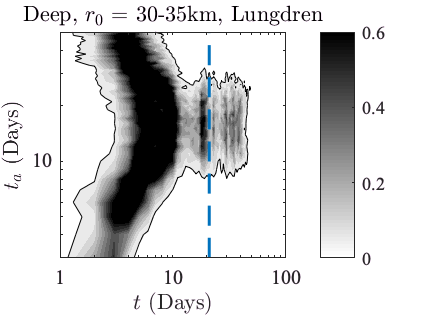

figure('unit','inches','pos',[0. 0. 2.99, 2.2], 'renderer','painters')
levs = [0:0.05:1]; 

colormap(flipud(gray))
% obs 
i=2;  % dist class 
j=2;  % depth 

id = find( Obs_disp(j,i).avdisp.^0.5/1e3<=100 ,1, 'last');

contourf(log10(Tdisp+0.01), log10(Tfit_ax), fitting_obs(j,i).p_lung', levs, 'edgecolor', 'none')
caxis([0 0.6])
hold all 
contour(log10(Tdisp+0.01), log10(Tfit_ax), fitting_obs(j,i).p_lung', [0.05 0.05], 'edgecolor', 'k')
plot( log10(Tdisp(id)+0.01)* Tfit_ax./Tfit_ax, log10(Tfit_ax), '--', 'linewidth',1.5)

xlabel('t (days)')
xlim([0 2])
cb = colorbar();
%a =  cb.Position; %gets the positon and size of the color bar
%set(cb,'Position',[a(1) a(2) a(3)/2 a(4)])% To change size

ticks4x = [log10(1:10) , log10(20:10:100)];
xticks(ticks4x)
xticklabels({'1', '', '','','','','','','','10','','','','','','','','', '100'})
ticks4y = [log10(1:10) , log10(20:10:100), log10(200:100:300)];
yticks(ticks4y)
yticklabels({'1','', '','','','','','','','10','','','','','','','','', '100'})

set(gca,'fontsize', 10, 'fontname','times')
xlabel('$t$ (Days)', 'interpreter', 'latex')
ylabel('$t_a$ (Days)', 'interpreter', 'latex')
title('Deep, $r_0$ = 30-35km, Lungdren', 'interpreter', 'latex')

print('obsKS_lung_22.eps','-depsc', '-r400')

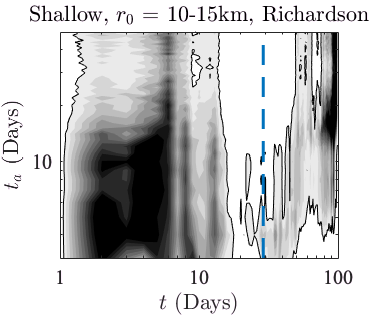


figure('unit','inches','pos',[0. 0. 2.6, 2.2], 'renderer','OpenGL')
levs = [0:0.05:1]; 

colormap(flipud(gray))
% obs 
i=1;  % dist class 
j=1;  % depth 

id = find( Obs_disp(j,i).avdisp.^0.5/1e3<=100 ,1, 'last');

contourf(log10(Tdisp+0.01), log10(Tfit_ax), fitting_obs(j,i).p_rich', levs, 'edgecolor', 'none')
caxis([0 0.6])
hold all 
contour(log10(Tdisp+0.01), log10(Tfit_ax), fitting_obs(j,i).p_rich', [0.05 0.05], 'edgecolor', 'k')
plot( log10(Tdisp(id)+0.01)* Tfit_ax./Tfit_ax, log10(Tfit_ax), '--', 'linewidth',1.5)

xlabel('t (days)')
xlim([0 2])

ticks4x = [log10(1:10) , log10(20:10:100)];
xticks(ticks4x)
xticklabels({'1', '', '','','','','','','','10','','','','','','','','', '100'})
ticks4y = [log10(1:10) , log10(20:10:100), log10(200:100:300)];
yticks(ticks4y)
yticklabels({'1','', '','','','','','','','10','','','','','','','','', '100'})

set(gca,'fontsize', 10, 'fontname','times')
xlabel('$t$ (Days)', 'interpreter', 'latex')
ylabel('$t_a$ (Days)', 'interpreter', 'latex')
title('Shallow, $r_0$ = 10-15km, Richardson', 'interpreter', 'latex')

print('obsKS_rich_11.eps','-depsc', '-r400')

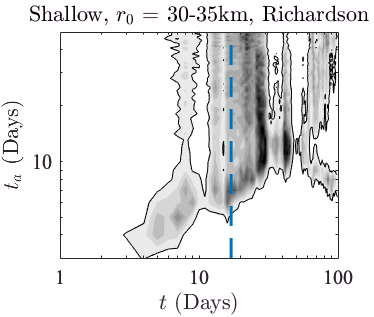

figure('unit','inches','pos',[0. 0. 2.6, 2.2], 'renderer','OpenGL')
levs = [0:0.05:1]; 

colormap(flipud(gray))
% obs 
i=2;  % dist class 
j=1;  % depth 

id = find( Obs_disp(j,i).avdisp.^0.5/1e3<=100 ,1, 'last');

contourf(log10(Tdisp+0.01), log10(Tfit_ax), fitting_obs(j,i).p_rich', levs, 'edgecolor', 'none')
caxis([0 0.6])
hold all 
contour(log10(Tdisp+0.01), log10(Tfit_ax), fitting_obs(j,i).p_rich', [0.05 0.05], 'edgecolor', 'k')
plot( log10(Tdisp(id)+0.01)* Tfit_ax./Tfit_ax, log10(Tfit_ax), '--', 'linewidth',1.5)

xlabel('t (days)')
xlim([0 2])

ticks4x = [log10(1:10) , log10(20:10:100)];
xticks(ticks4x)
xticklabels({'1', '', '','','','','','','','10','','','','','','','','', '100'})
ticks4y = [log10(1:10) , log10(20:10:100), log10(200:100:300)];
yticks(ticks4y)
yticklabels({'1','', '','','','','','','','10','','','','','','','','', '100'})

set(gca,'fontsize', 10, 'fontname','times')
xlabel('$t$ (Days)', 'interpreter', 'latex')
ylabel('$t_a$ (Days)', 'interpreter', 'latex')
title('Shallow, $r_0$ = 30-35km, Richardson', 'interpreter', 'latex')

print('obsKS_rich_21.eps','-depsc', '-r400')

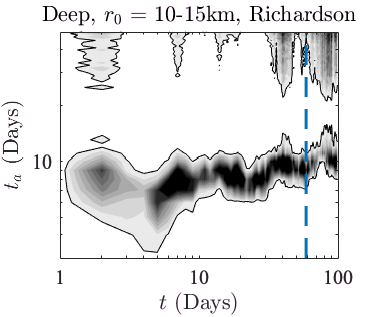

figure('unit','inches','pos',[0. 0. 2.6, 2.2], 'renderer','OpenGL')
levs = [0:0.05:1]; 

colormap(flipud(gray))
% obs 
i=1;  % dist class 
j=2;  % depth 

id = find( Obs_disp(j,i).avdisp.^0.5/1e3<=100 ,1, 'last');

contourf(log10(Tdisp+0.01), log10(Tfit_ax), fitting_obs(j,i).p_rich', levs, 'edgecolor', 'none')
caxis([0 0.6])
hold all 
contour(log10(Tdisp+0.01), log10(Tfit_ax), fitting_obs(j,i).p_rich', [0.05 0.05], 'edgecolor', 'k')
plot( log10(Tdisp(id)+0.01)* Tfit_ax./Tfit_ax, log10(Tfit_ax), '--', 'linewidth',1.5)

xlabel('t (days)')
xlim([0 2])

ticks4x = [log10(1:10) , log10(20:10:100)];
xticks(ticks4x)
xticklabels({'1', '', '','','','','','','','10','','','','','','','','', '100'})
ticks4y = [log10(1:10) , log10(20:10:100), log10(200:100:300)];
yticks(ticks4y)
yticklabels({'1','', '','','','','','','','10','','','','','','','','', '100'})

set(gca,'fontsize', 10, 'fontname','times')
xlabel('$t$ (Days)', 'interpreter', 'latex')
ylabel('$t_a$ (Days)', 'interpreter', 'latex')
title('Deep, $r_0$ = 10-15km, Richardson', 'interpreter', 'latex')

print('obsKS_rich_12.eps','-depsc', '-r400')

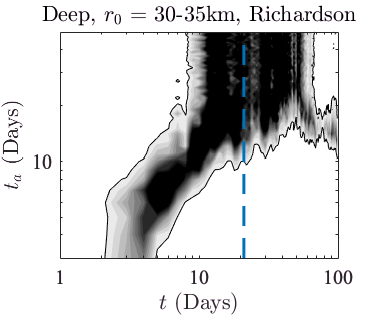

figure('unit','inches','pos',[0. 0. 2.6, 2.2], 'renderer','OpenGL')
levs = [0:0.05:1]; 

colormap(flipud(gray))
% obs 
i=2;  % dist class 
j=2;  % depth 

id = find( Obs_disp(j,i).avdisp.^0.5/1e3<=100 ,1, 'last');

contourf(log10(Tdisp+0.01), log10(Tfit_ax), fitting_obs(j,i).p_rich', levs, 'edgecolor', 'none')
caxis([0 0.6])
hold all 
contour(log10(Tdisp+0.01), log10(Tfit_ax), fitting_obs(j,i).p_rich', [0.05 0.05], 'edgecolor', 'k')
plot( log10(Tdisp(id)+0.01)* Tfit_ax./Tfit_ax, log10(Tfit_ax), '--', 'linewidth',1.5)

xlabel('t (days)')
xlim([0 2])

ticks4x = [log10(1:10) , log10(20:10:100)];
xticks(ticks4x)
xticklabels({'1', '', '','','','','','','','10','','','','','','','','', '100'})
ticks4y = [log10(1:10) , log10(20:10:100), log10(200:100:300)];
yticks(ticks4y)
yticklabels({'1','', '','','','','','','','10','','','','','','','','', '100'})

set(gca,'fontsize', 10, 'fontname','times')
xlabel('$t$ (Days)', 'interpreter', 'latex')
ylabel('$t_a$ (Days)', 'interpreter', 'latex')
title('Deep, $r_0$ = 30-35km, Richardson', 'interpreter', 'latex')

print('obsKS_rich_22.eps','-depsc', '-r400')

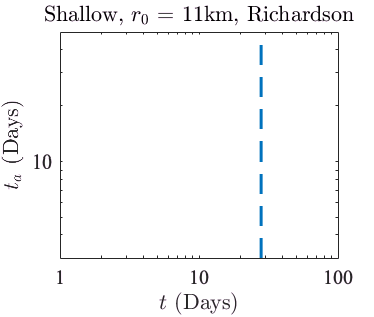

figure('unit','inches','pos',[0. 0. 2.6, 2.2], 'renderer','OpenGL')
levs = [0:0.05:1]; 

colormap(flipud(gray))
% obs 
i=1;  % dist class 
j=1;  % depth 

id = find( Mod_disp(j,i).avdisp.^0.5/1e3<=100 ,1, 'last');

contourf(log10(Tdisp+0.01), log10(Tfit_ax), fitting_mod(j,i).p_rich', levs, 'edgecolor', 'none')
caxis([0 0.6])
hold all 
contour(log10(Tdisp+0.01), log10(Tfit_ax), fitting_mod(j,i).p_rich', [0.05 0.05], 'edgecolor', 'k')
plot( log10(Tdisp(id)+0.01)* Tfit_ax./Tfit_ax, log10(Tfit_ax), '--', 'linewidth',1.5)

xlabel('t (days)')
xlim([0 2])

ticks4x = [log10(1:10) , log10(20:10:100)];
xticks(ticks4x)
xticklabels({'1', '', '','','','','','','','10','','','','','','','','', '100'})
ticks4y = [log10(1:10) , log10(20:10:100), log10(200:100:300)];
yticks(ticks4y)
yticklabels({'1','', '','','','','','','','10','','','','','','','','', '100'})

set(gca,'fontsize', 10, 'fontname','times')
xlabel('$t$ (Days)', 'interpreter', 'latex')
ylabel('$t_a$ (Days)', 'interpreter', 'latex')
title('Shallow, $r_0$ = 11km, Richardson', 'interpreter', 'latex')

print('modKS_rich_11.eps','-depsc', '-r400')

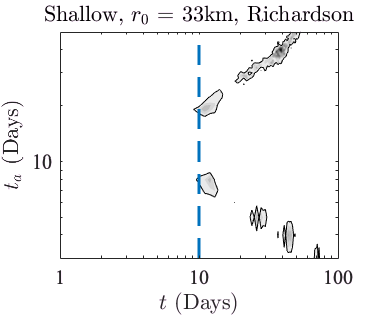

figure('unit','inches','pos',[0. 0. 2.6, 2.2], 'renderer','OpenGL')
levs = [0:0.05:1]; 

colormap(flipud(gray))
% obs 
i=2;  % dist class 
j=1;  % depth 

id = find( Mod_disp(j,i).avdisp.^0.5/1e3<=100 ,1, 'last');

contourf(log10(Tdisp+0.01), log10(Tfit_ax), fitting_mod(j,i).p_rich', levs, 'edgecolor', 'none')
caxis([0 0.6])
hold all 
contour(log10(Tdisp+0.01), log10(Tfit_ax), fitting_mod(j,i).p_rich', [0.05 0.05], 'edgecolor', 'k')
plot( log10(Tdisp(id)+0.01)* Tfit_ax./Tfit_ax, log10(Tfit_ax), '--', 'linewidth',1.5)

xlabel('t (days)')
xlim([0 2])

ticks4x = [log10(1:10) , log10(20:10:100)];
xticks(ticks4x)
xticklabels({'1', '', '','','','','','','','10','','','','','','','','', '100'})
ticks4y = [log10(1:10) , log10(20:10:100), log10(200:100:300)];
yticks(ticks4y)
yticklabels({'1','', '','','','','','','','10','','','','','','','','', '100'})

set(gca,'fontsize', 10, 'fontname','times')
xlabel('$t$ (Days)', 'interpreter', 'latex')
ylabel('$t_a$ (Days)', 'interpreter', 'latex')
title('Shallow, $r_0$ = 33km, Richardson', 'interpreter', 'latex')

print('modKS_rich_21.eps','-depsc', '-r400')

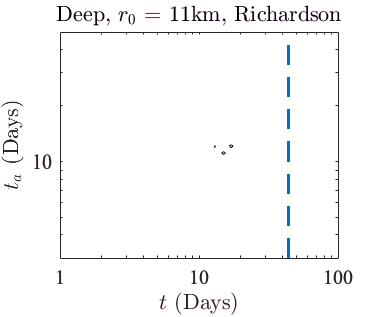

figure('unit','inches','pos',[0. 0. 2.6, 2.2], 'renderer','OpenGL')
levs = [0:0.05:1]; 

colormap(flipud(gray))
% obs 
i=1;  % dist class 
j=2;  % depth 

id = find( Mod_disp(j,i).avdisp.^0.5/1e3<=100 ,1, 'last');

contourf(log10(Tdisp+0.01), log10(Tfit_ax), fitting_mod(j,i).p_rich', levs, 'edgecolor', 'none')
caxis([0 0.6])
hold all 
contour(log10(Tdisp+0.01), log10(Tfit_ax), fitting_mod(j,i).p_rich', [0.05 0.05], 'edgecolor', 'k')
plot( log10(Tdisp(id)+0.01)* Tfit_ax./Tfit_ax, log10(Tfit_ax), '--', 'linewidth',1.5)

xlabel('t (days)')
xlim([0 2])

ticks4x = [log10(1:10) , log10(20:10:100)];
xticks(ticks4x)
xticklabels({'1', '', '','','','','','','','10','','','','','','','','', '100'})
ticks4y = [log10(1:10) , log10(20:10:100), log10(200:100:300)];
yticks(ticks4y)
yticklabels({'1','', '','','','','','','','10','','','','','','','','', '100'})

set(gca,'fontsize', 10, 'fontname','times')
xlabel('$t$ (Days)', 'interpreter', 'latex')
ylabel('$t_a$ (Days)', 'interpreter', 'latex')
title('Deep, $r_0$ = 11km, Richardson', 'interpreter', 'latex')

print('modKS_rich_12.eps','-depsc', '-r400')

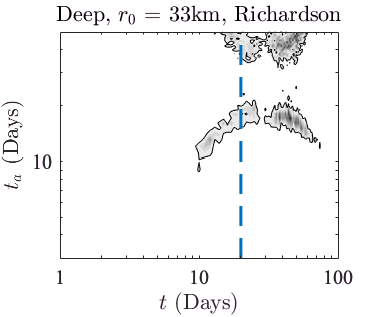

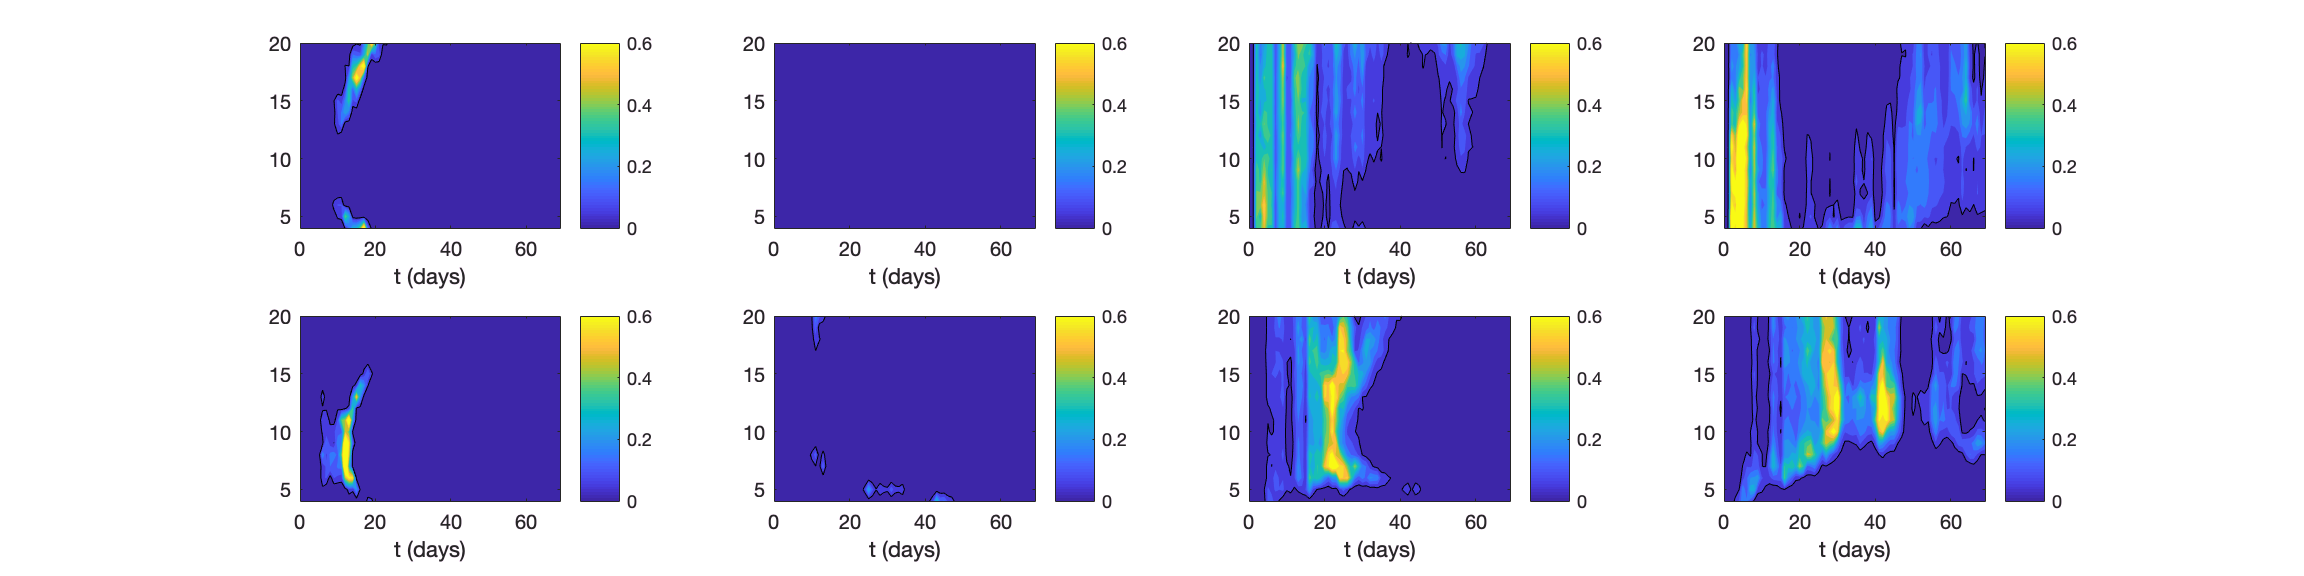

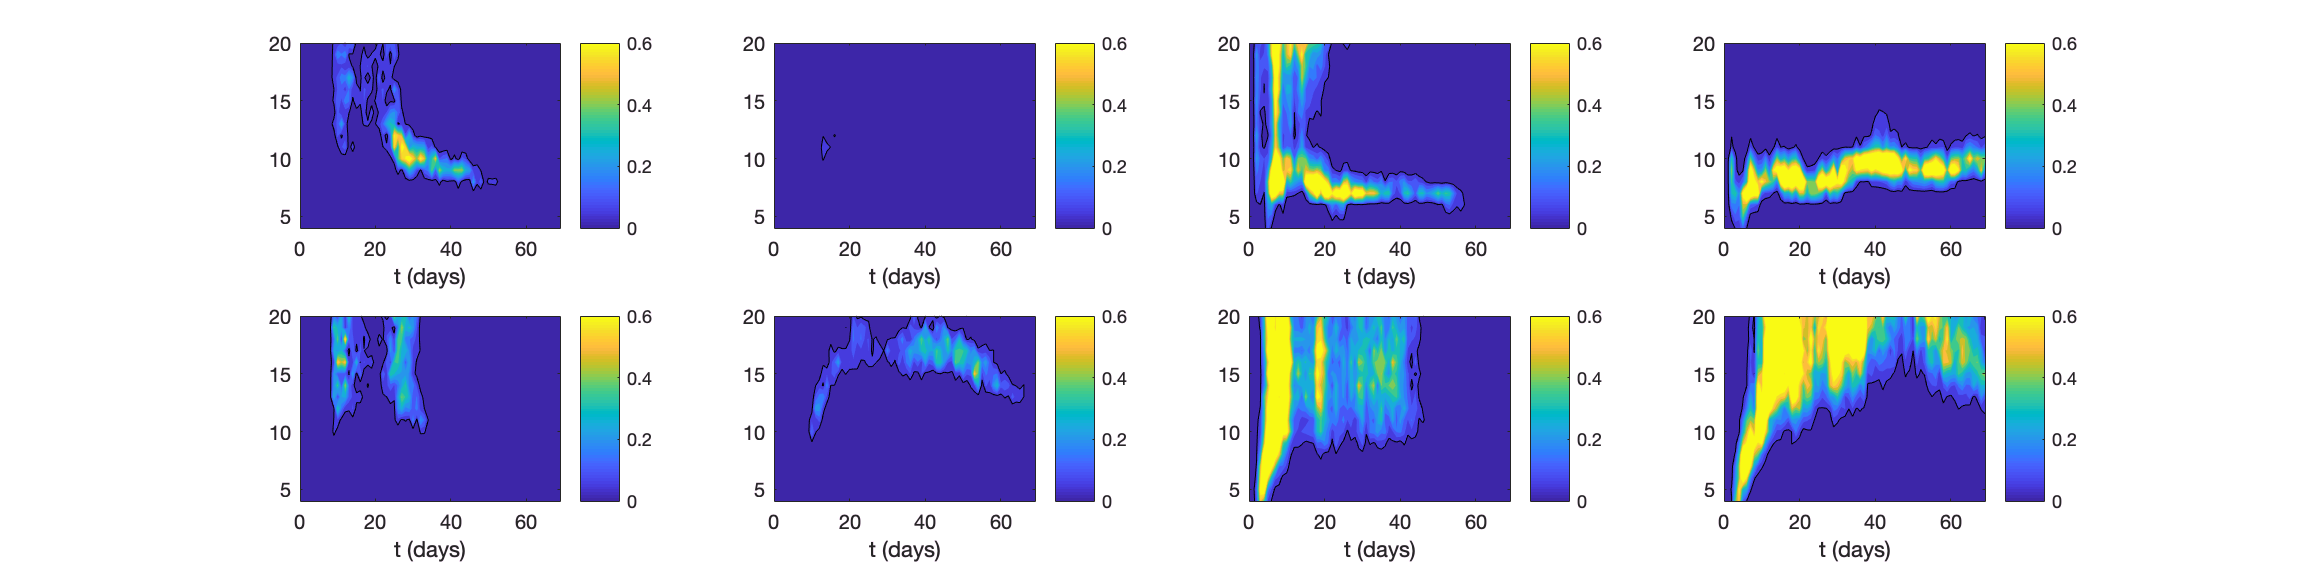

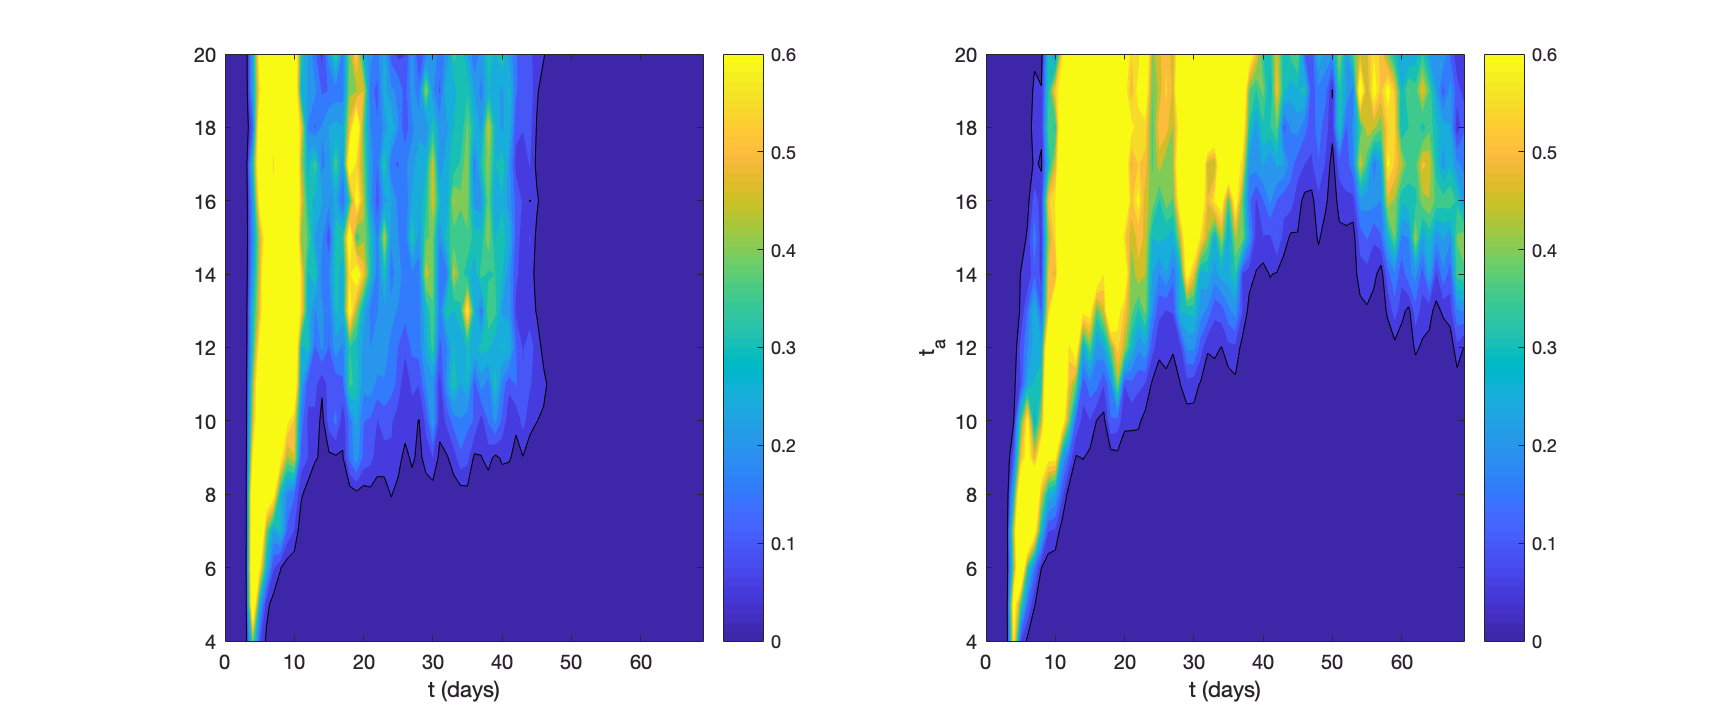

figure('unit','inches','pos',[0. 0. 2.6, 2.2], 'renderer','OpenGL')
levs = [0:0.05:1]; 

colormap(flipud(gray))
% obs 
i=2;  % dist class 
j=2;  % depth 

id = find( Mod_disp(j,i).avdisp.^0.5/1e3<=100 ,1, 'last');

contourf(log10(Tdisp+0.01), log10(Tfit_ax), fitting_mod(j,i).p_rich', levs, 'edgecolor', 'none')
caxis([0 0.6])
hold all 
contour(log10(Tdisp+0.01), log10(Tfit_ax), fitting_mod(j,i).p_rich', [0.05 0.05], 'edgecolor', 'k')
plot( log10(Tdisp(id)+0.01)* Tfit_ax./Tfit_ax, log10(Tfit_ax), '--', 'linewidth',1.5)

xlabel('t (days)')
xlim([0 2])

ticks4x = [log10(1:10) , log10(20:10:100)];
xticks(ticks4x)
xticklabels({'1', '', '','','','','','','','10','','','','','','','','', '100'})
ticks4y = [log10(1:10) , log10(20:10:100), log10(200:100:300)];
yticks(ticks4y)
yticklabels({'1','', '','','','','','','','10','','','','','','','','', '100'})

set(gca,'fontsize', 10, 'fontname','times')
xlabel('$t$ (Days)', 'interpreter', 'latex')
ylabel('$t_a$ (Days)', 'interpreter', 'latex')
title('Deep, $r_0$ = 33km, Richardson', 'interpreter', 'latex')

print('modKS_rich_22.eps','-depsc', '-r400')